**Resolución del problema directo.**

Esquema de diferencias finitas estudiado en el Proyecto 2. 

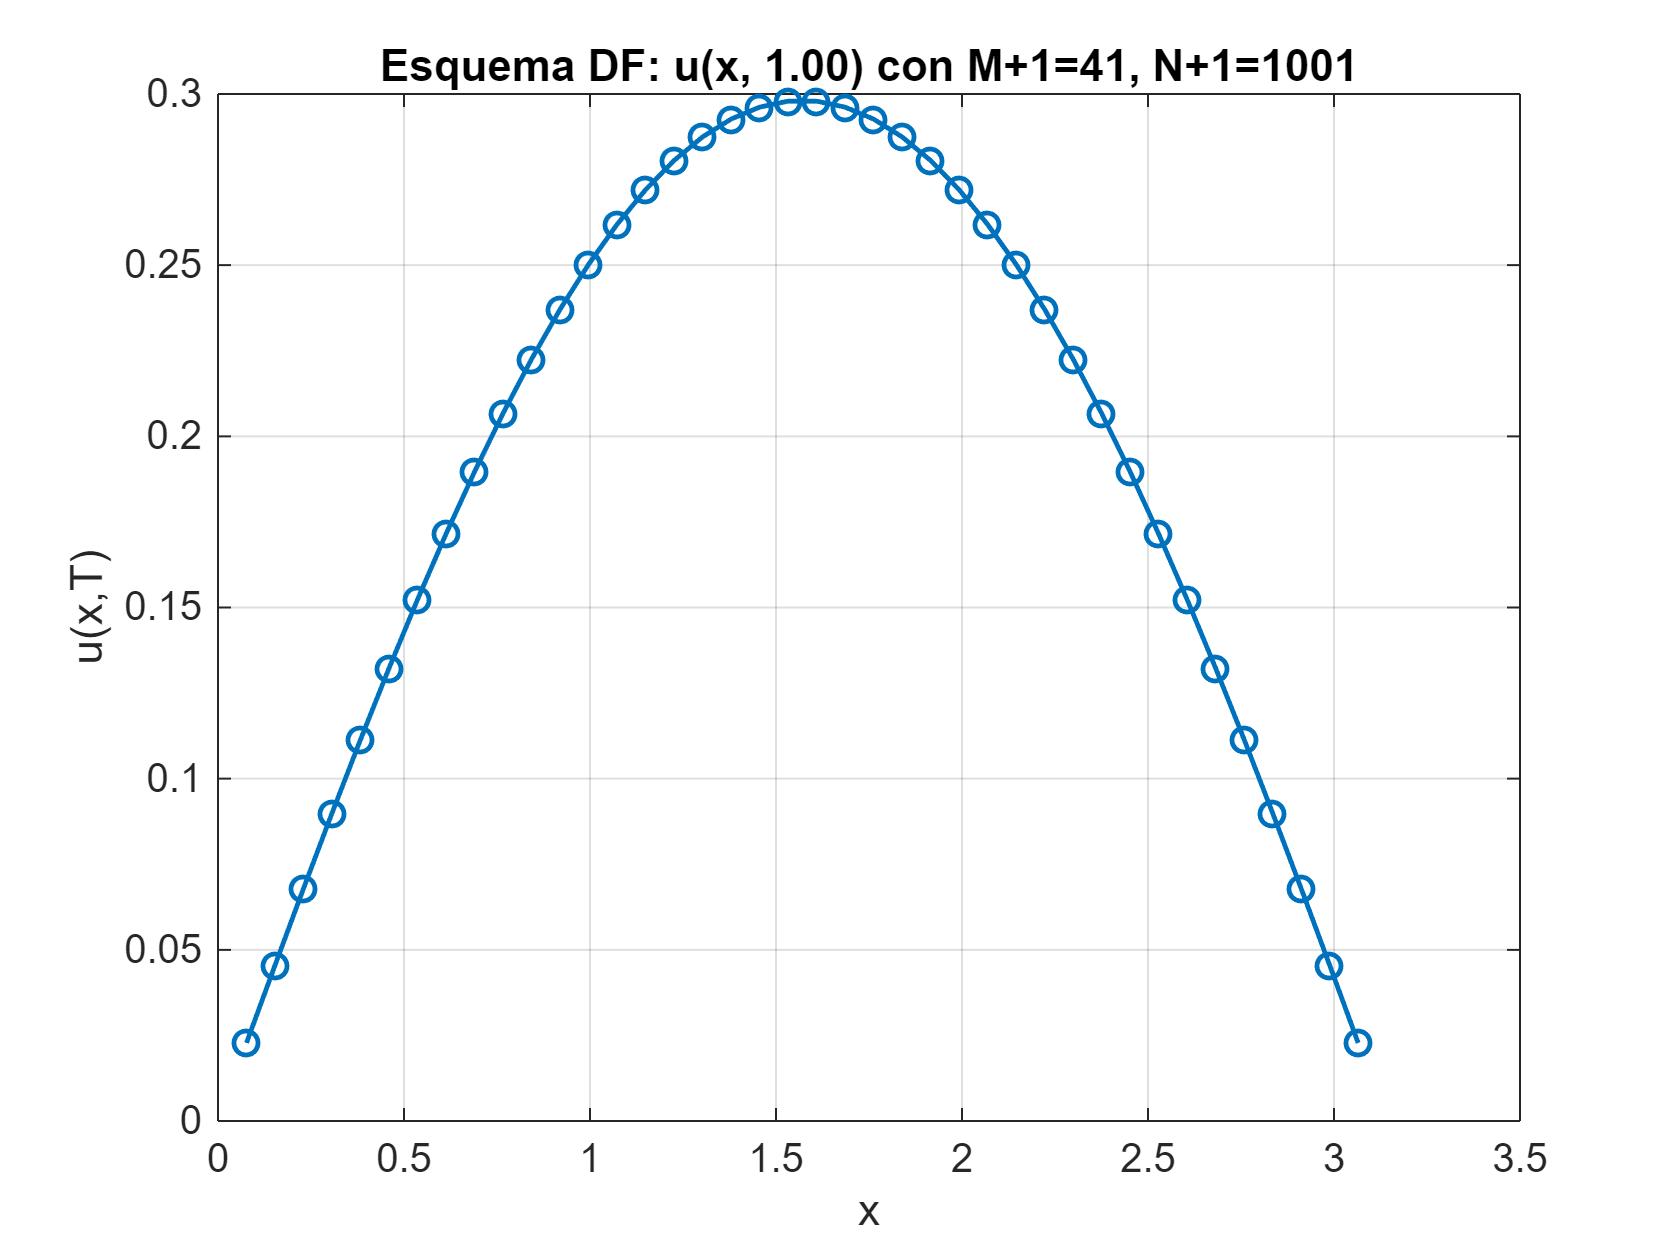


% Parámetros
L     = pi;
M_df  = 40;                        % M+1 = 41                    
dx    = L / (M_df+1);                
x     = (1:M_df)'*dx;              

T = 1 ;         % T = 0.1, 1                   
N_df     = 1000;                   % N+1 = 1001
dt    = T / (N_df + 1);            % 9.99e-4
d     = dt / (dx^2);              

% Matriz A 
e     = ones(M_df,1);
A     = spdiags([d*e, (1-2*d)*e, d*e], -1:1, M_df, M_df);

% Condición inicial f(x)
u_x0    = (2/pi)*x .* (x <= L/2) + (2/pi)*(L - x) .* (x > L/2);

% Iteración temporal 
u     = u_x0;
for j = 1:(N_df+1)
    u = A*u;
end

xDiferenciasFinitas = x;
uDiferenciasFinitas = u;

% Representación
figure;
plot(xDiferenciasFinitas, uDiferenciasFinitas, '-o','LineWidth',1.2);
xlabel('x');
ylabel('u(x,T)');
title(sprintf('Esquema DF: u(x, %.2f) con M+1=%d, N+1=%d', T, M_df+1, N_df+1));
grid on

Nuevo método definido en el proyecto 3. 

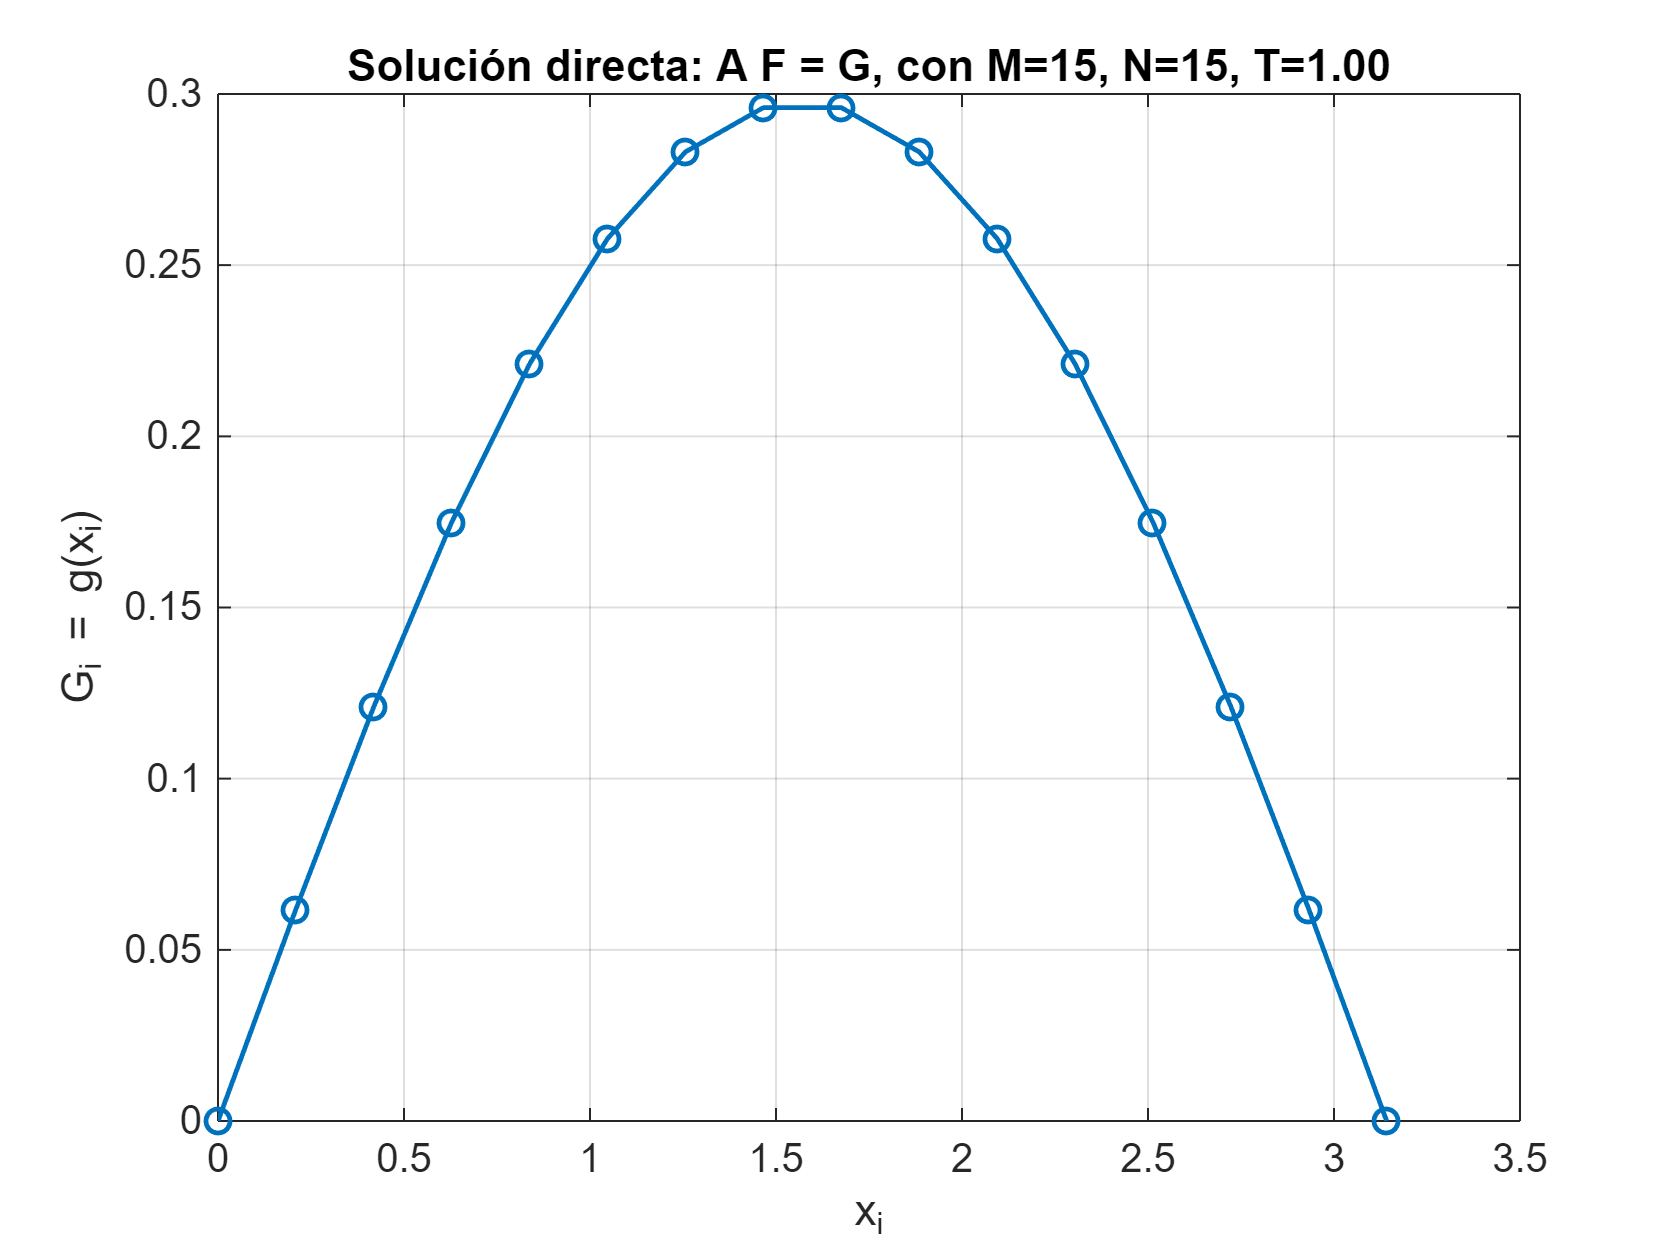

% Parámetros 
L= pi;         
M = 15;    %15, 30    
N = 15;     %5, 10, 15  

% Pasos en y y nodos
dy = L / M;
yi = (0:M)' * dy;      % j = 0,...,M

% Vector F = [f(y0); f(y1); …; f(yM)]
F = (2/pi)*yi .* (yi<=L/2) + (2/pi)*(L - yi) .* (yi > L/2);

% Pesos del trapecio
w = ones(M+1,1);
w(2:end-1) = 2;

% Matriz A
A = zeros(M+1, M+1);

for i = 1:(M+1)
  x_i = (i-1)*dy;
  for j = 1:(M+1)
    y_j = (j-1)*dy;
    % suma K
    s = 0;
    for n = 1:N
      s = s + exp(- (n*pi)^2 * T / L^2) * sin(n*pi*x_i/L) * sin(n*pi*y_j/L);
    end
    Kij = (2/L) * s;
    A(i,j) = (L/(2*M)) * w(j) * Kij;
  end
end

% Ahora calculamos G = A * F
G = A * F;

% Representación
xi = (0:M)' * dy;
figure
plot(xi, G, '-o','LineWidth',1.2)
xlabel('x_i')
ylabel('G_i = g(x_i)')
title(sprintf('Solución directa: A F = G, con M=%d, N=%d, T=%.2f', M, N, T))
grid on

uEspectral = spline(xDiferenciasFinitas, uDiferenciasFinitas,xi);

err_rel = max(abs(G - uEspectral)) / max(abs(uEspectral));
fprintf('Incremento de x: %.5f\n', dy);

Incremento de x: 0.20944


fprintf('Error relativo cuando T = %.2f\n, M = %d, N = %d: E = %.10f\n', T,  M, N,  err_rel);

Error relativo cuando T = 1.00
, M = 15, N = 15: E = 0.0015806337


**Resolución del problema inverso**

Ejercicio 2 - Apartado 1: Aproximación u(x,0.4) por diferencias finitas

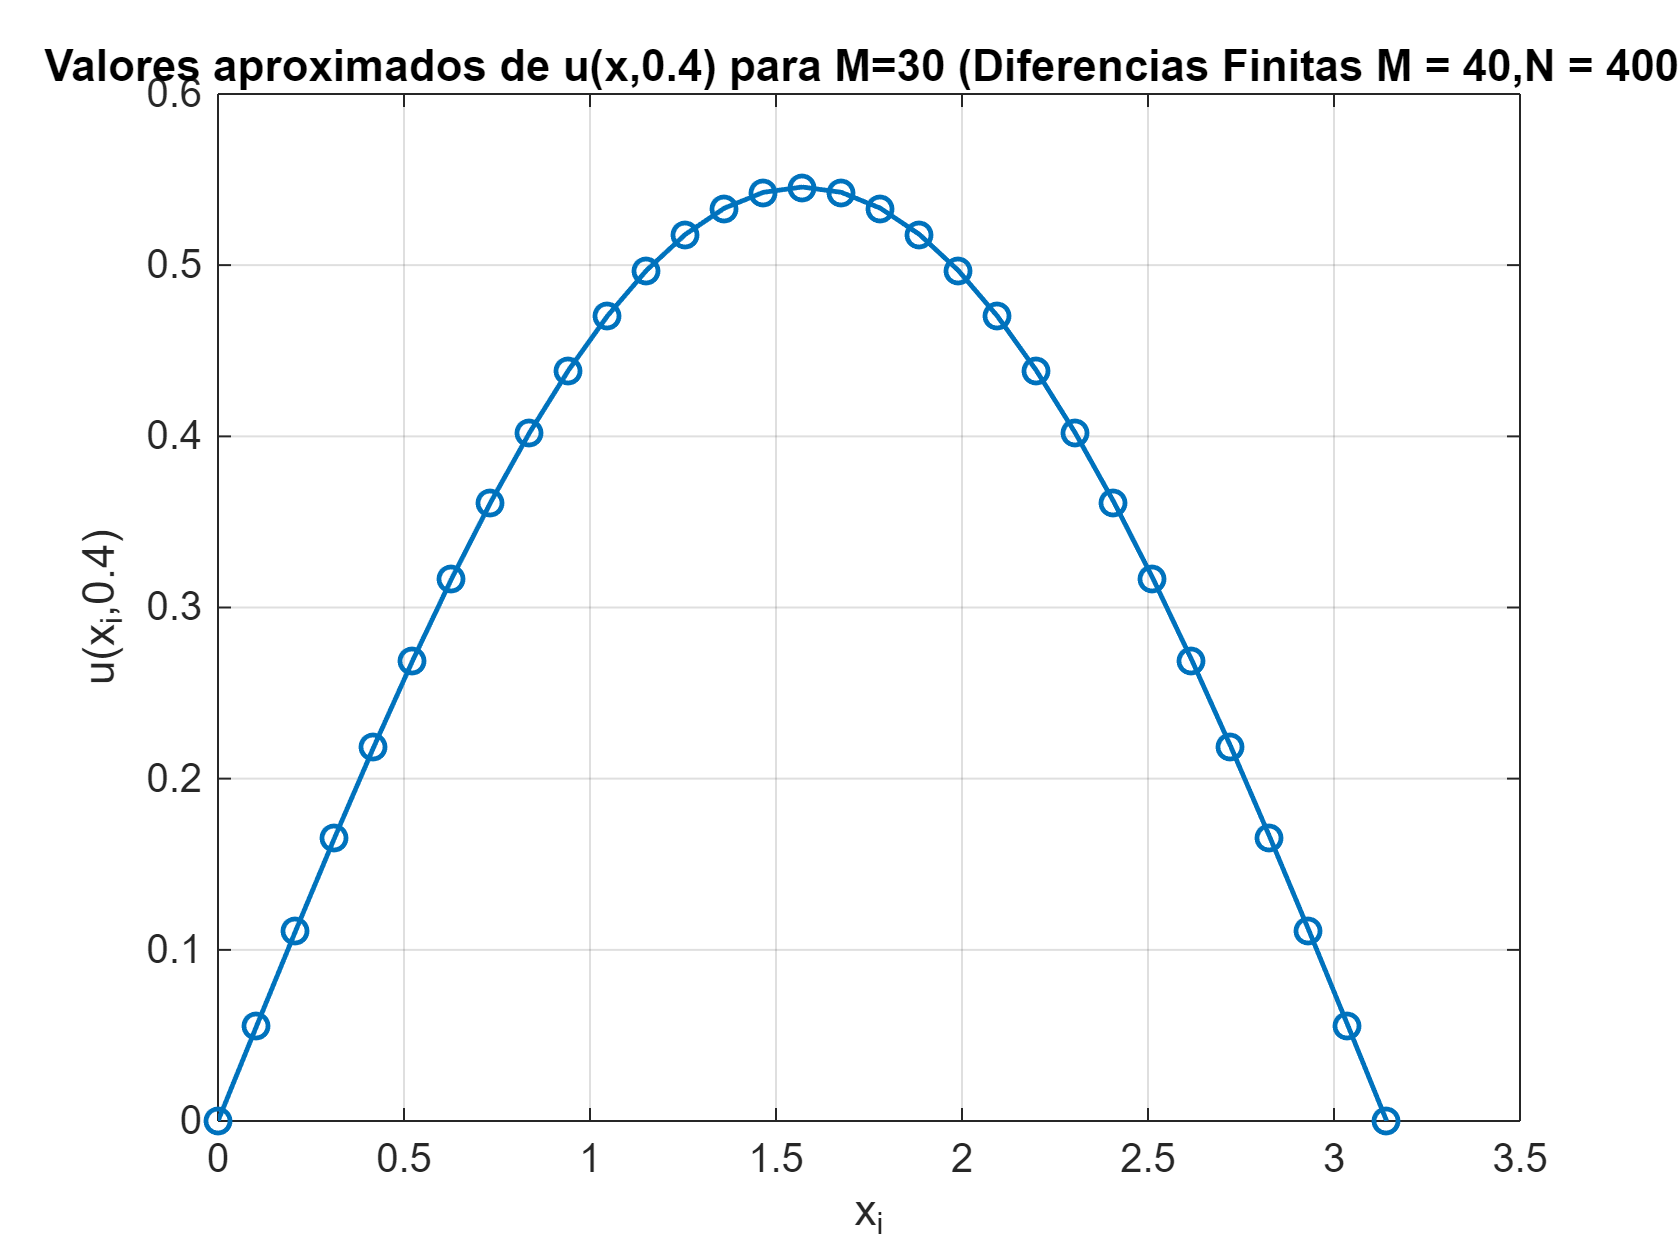

% Parámetros
L = pi;            
Mdf = 40;           
Ndf = 400;           
T   = 0.4;           

dx = L / (Mdf+1);
dt = T / (Ndf+1);
d = dt / dx^2;          % 0 < d < 1/2

% malla para DF
xDiferenciasFinitas = (1:Mdf)' * dx;

% matriz A_df
e  = ones(Mdf, 1);
A_df = spdiags([d*e, (1-2*d)*e, d*e], -1:1, Mdf, Mdf);

% condición inicial
fDiferenciasFinitas = (2/pi)*xDiferenciasFinitas .* (xDiferenciasFinitas <= L/2) ...
    + (2/pi)*(L - xDiferenciasFinitas) .* (xDiferenciasFinitas > L/2);

% Iterar esquema Diferecnias Finitas hasta t = 0.4
% t = (Ndf +1)dt = (Ndf +1)T/(Ndf+1) = T = 0.4
u = fDiferenciasFinitas;
for j = 1:(Ndf+1)
  u = A_df * u;
end
uDiferenciasFinitas = u;   

% Interpolar en la malla M = 30
M = 30;
xi = (0:M)' * (L/M);      % nodos xi = iL / M, i=0,...,M

% construir vector de datos u_data en xi
u_aprox = zeros(M+1,1);
u_aprox(2:end-1) = ...
   spline(xDiferenciasFinitas, uDiferenciasFinitas, xi(2:end-1)); %u(0,t)=u(pi,t)=0 

% Fichero
save('datos_T04_M30.mat','xi','u_aprox');

% Gráfica
figure;
plot(xi, u_aprox, 'o-','LineWidth',1.2); xlabel('x_i'); ylabel('u(x_i,0.4)');
title('Valores aproximados de u(x,0.4) para M=30 (Diferencias Finitas M = 40,N = 400)');
grid on

Ejercicio 2 - Apartado 2: Resolución del sistema AF = G ( M = 30 y N = 10) por método de Tikhonov

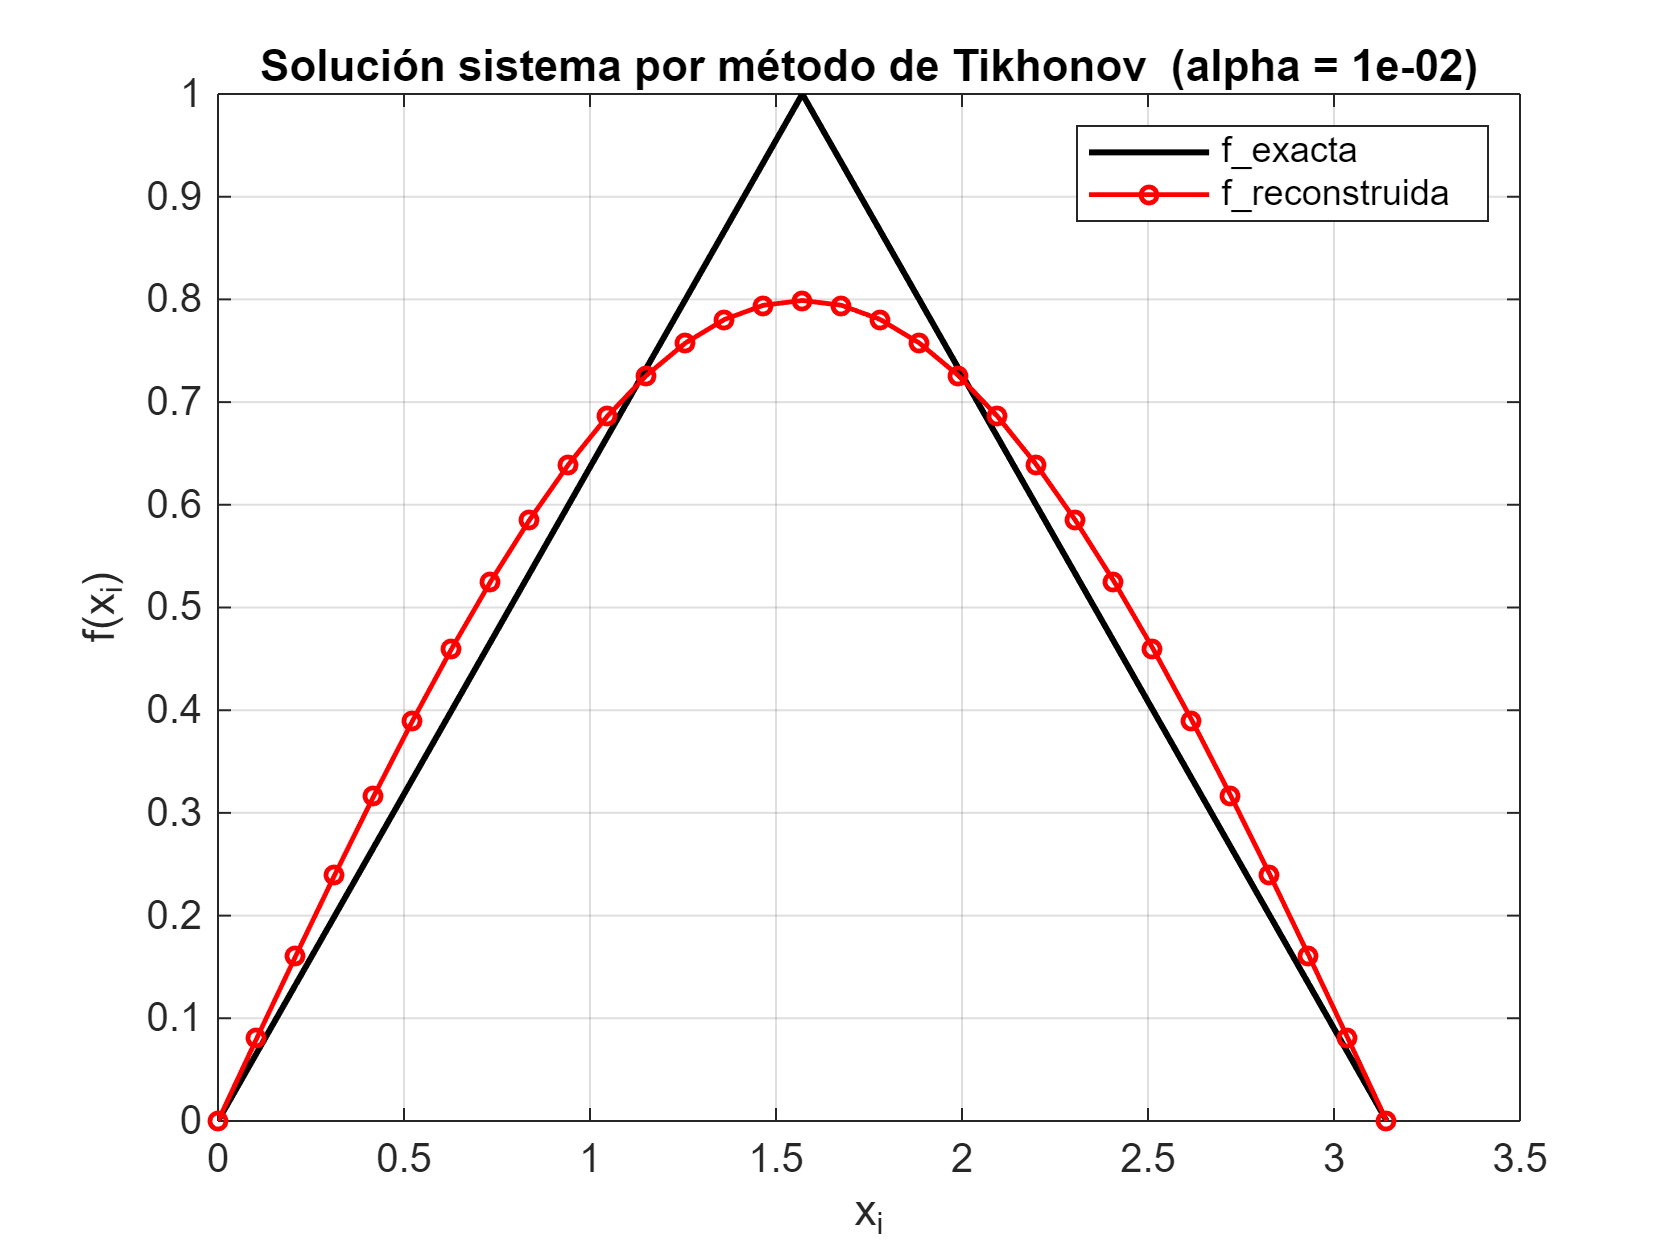

load('datos_T04_M30.mat','xi','u_aprox');   % xi: [0,pi] con M=30, u_aprox=G

% Matriz A para M=30, N=10, T=0.4
L  = pi;
M  = 30;         
N  = 10;          
T  = 0.4;         
dy = L / M;
yi = (0:M)' * dy;

% Trapecio compuesto
w = ones(M+1,1);
w(2:end-1) = 2;

% A(i,j)
A = zeros(M+1);
for i = 1:M+1
    x_i = (i-1)*dy;
    for j = 1:M+1
        y_j = (j-1)*dy;
        s = 0;
        for n = 1:N
            s = s + exp(-(n*pi)^2 * T / L^2) * ...
                    sin(n*pi*x_i / L) * sin(n*pi*y_j / L);
        end
        Kij      = (2/L) * s;
        A(i,j)   = (L/(2*M)) * w(j) * Kij;
    end
end

% Parámetro de Tikhonov y solución regularizada
alpha = 1e-2;                   
G = u_aprox;                    
F = tikhonov(A, G, alpha);  

% Temperatura inicial exacta 
f_inicial   = (2/pi)*xi .* (xi<=pi/2) + (2/pi)*(pi - xi) .* (xi>pi/2);

% Representación 
figure
plot(xi, f_inicial, 'k-', 'LineWidth', 1.5), hold on
plot(xi, F,'ro-', 'LineWidth', 1.2, 'MarkerSize',4)
xlabel('x_i'), ylabel('f(x_i)')
legend('f\_exacta','f\_reconstruida'), 
title(sprintf('Solución sistema por método de Tikhonov  (alpha = %.0e)',alpha))
grid on
hold off

Ejercicio 2 - Apartado 3: Reoslución del sistema AF = G por el método de Tikhonov iterado.

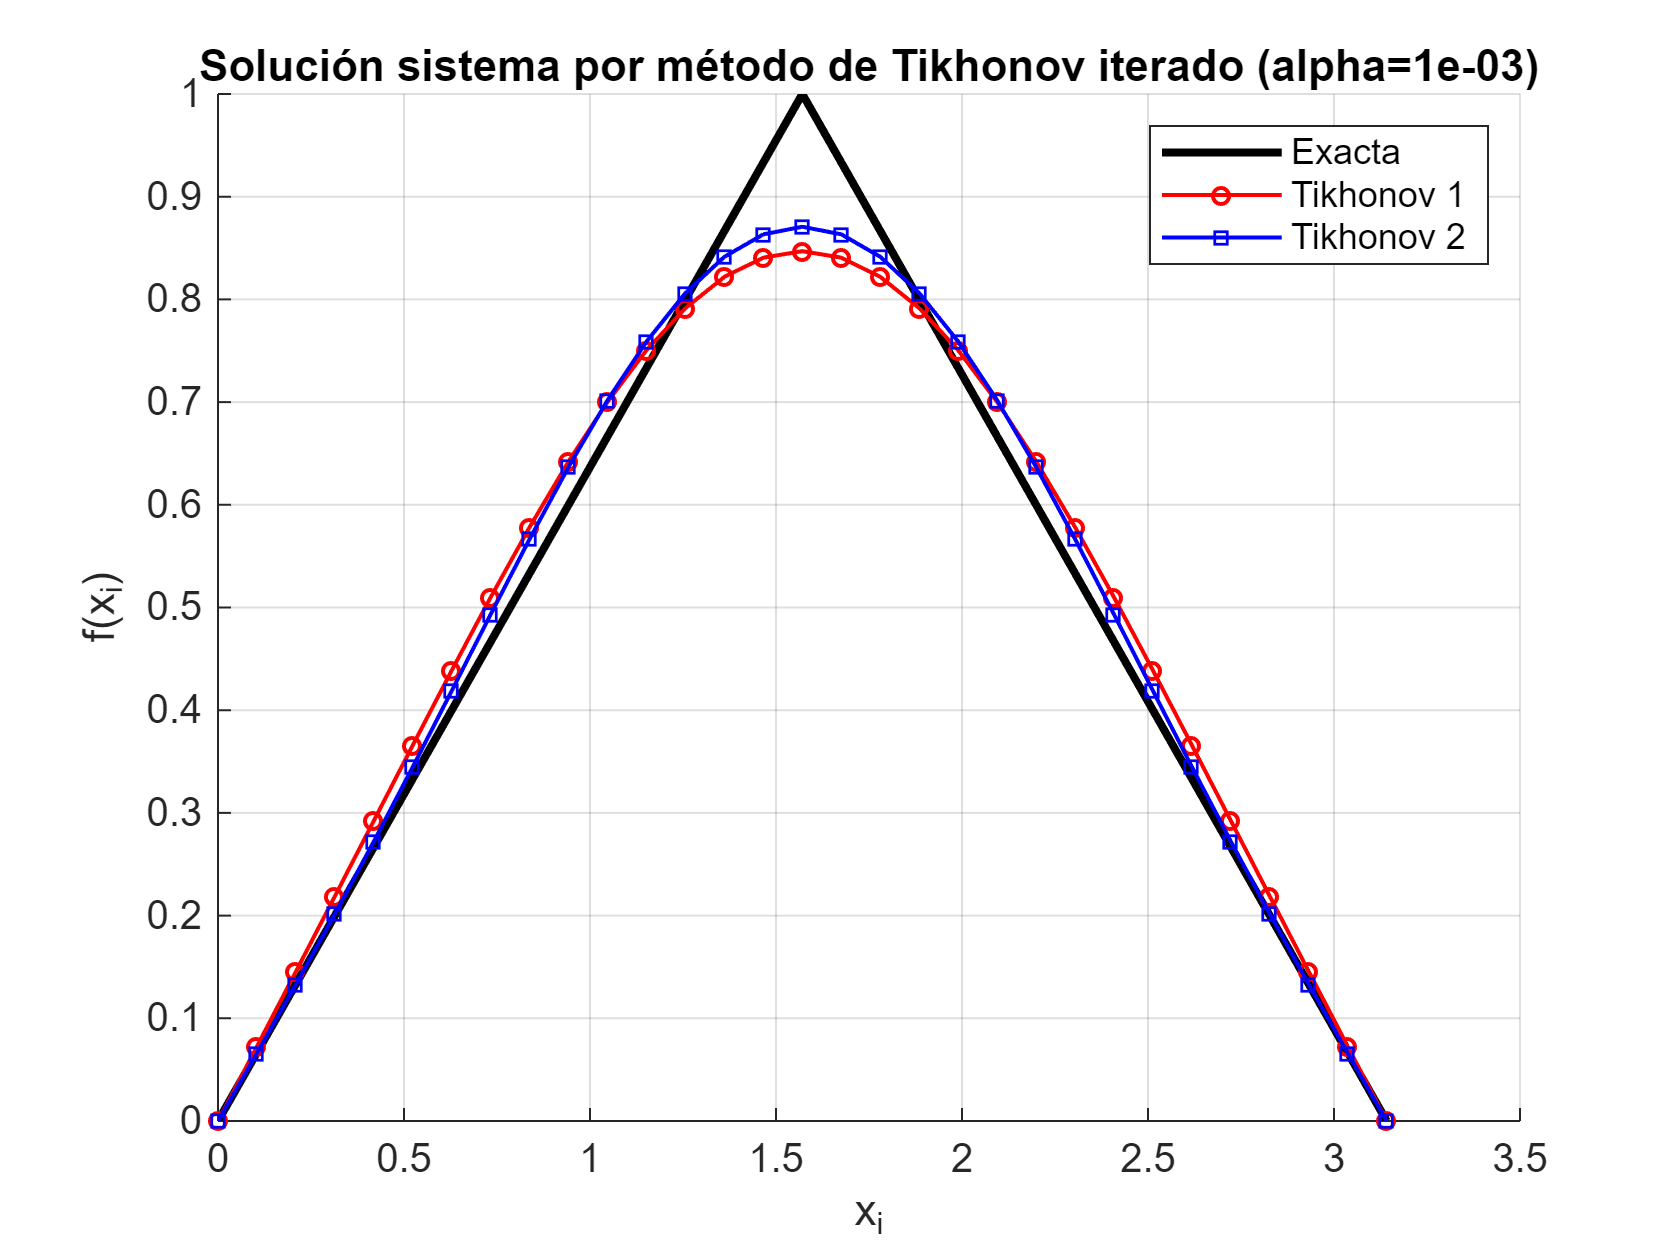

alpha = 1e-3;  

% Tikhonov n = 1 
x_1 = tikhonov_iterado(A, G, alpha, 1);

% Tikhonov n = 2
x_2 = tikhonov_iterado(A, G, alpha, 2);


% Función exacta
f_inicial = (2/pi)*xi .* (xi<=pi/2) + (2/pi)*(pi - xi) .* (xi>pi/2);

% Representación 
figure
hold on
plot(xi, f_inicial,   'k-',  'LineWidth',2);
plot(xi, x_1,   'ro-', 'LineWidth',1, 'MarkerSize',4);
plot(xi, x_2,   'bs-', 'LineWidth',1, 'MarkerSize',4);
legend('Exacta','Tikhonov 1','Tikhonov 2','Location','northeast');
xlabel('x_i'); ylabel('f(x_i)');
title(sprintf('Solución sistema por método de Tikhonov iterado (alpha=%.0e)', alpha));
grid on; hold off

Ejercicio 2 -  Apartado 4: Resolución sistema AF = G por método de Landwebber

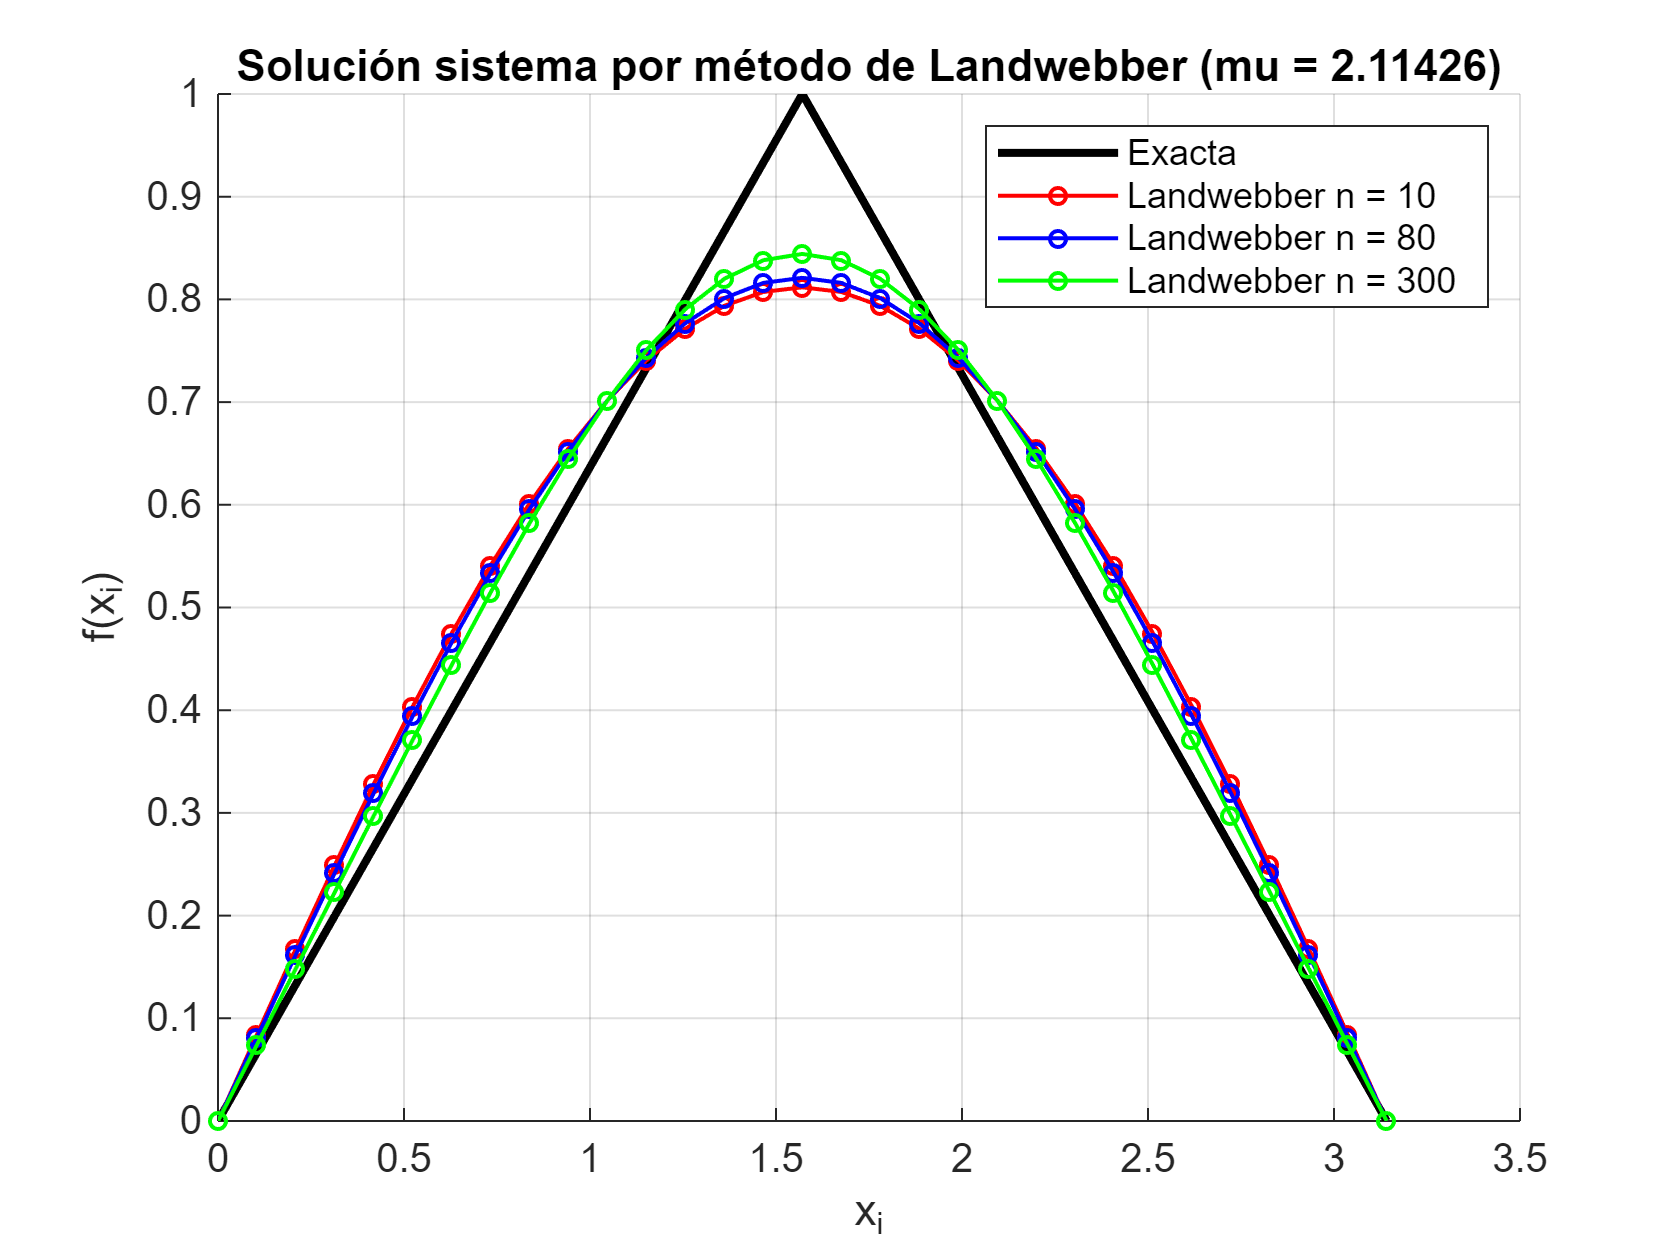

%% Apartado 4 - Resolución sistema AF = G por método de Landwebber

% Elección de mu

mu = 0.95 / norm(A'*A); %<1

% Landwebber n = 10
x_10 = landweber(A, G, mu, 10);

%Landwebber n = 80
x_80 = landweber(A, G, mu, 80);

%Landwebber n = 300
x_300 = landweber(A, G, mu, 300);

% Función exacta
f_inicial = (2/pi)*xi .* (xi<=pi/2) + (2/pi)*(pi - xi) .* (xi>pi/2);

% Representación 
figure; hold on
plot(xi, f_inicial,   'k-',  'LineWidth',2);
plot(xi, x_10,   'ro-', 'LineWidth',1, 'MarkerSize',4);
plot(xi, x_80,   'bo-', 'LineWidth',1, 'MarkerSize',4);
plot(xi, x_300,  'go-', 'LineWidth',1, 'MarkerSize',4);
legend('Exacta','Landwebber n = 10','Landwebber n = 80','Landwebber n = 300', 'Location','northeast');
xlabel('x_i'); ylabel('f(x_i)');
title(sprintf('Solución sistema por método de Landwebber (mu = %.5f)', mu));
grid on; hold off

Ejercicio 2 -  Apartado 5: Resolución sistema AF = G con perturbación en el vector G

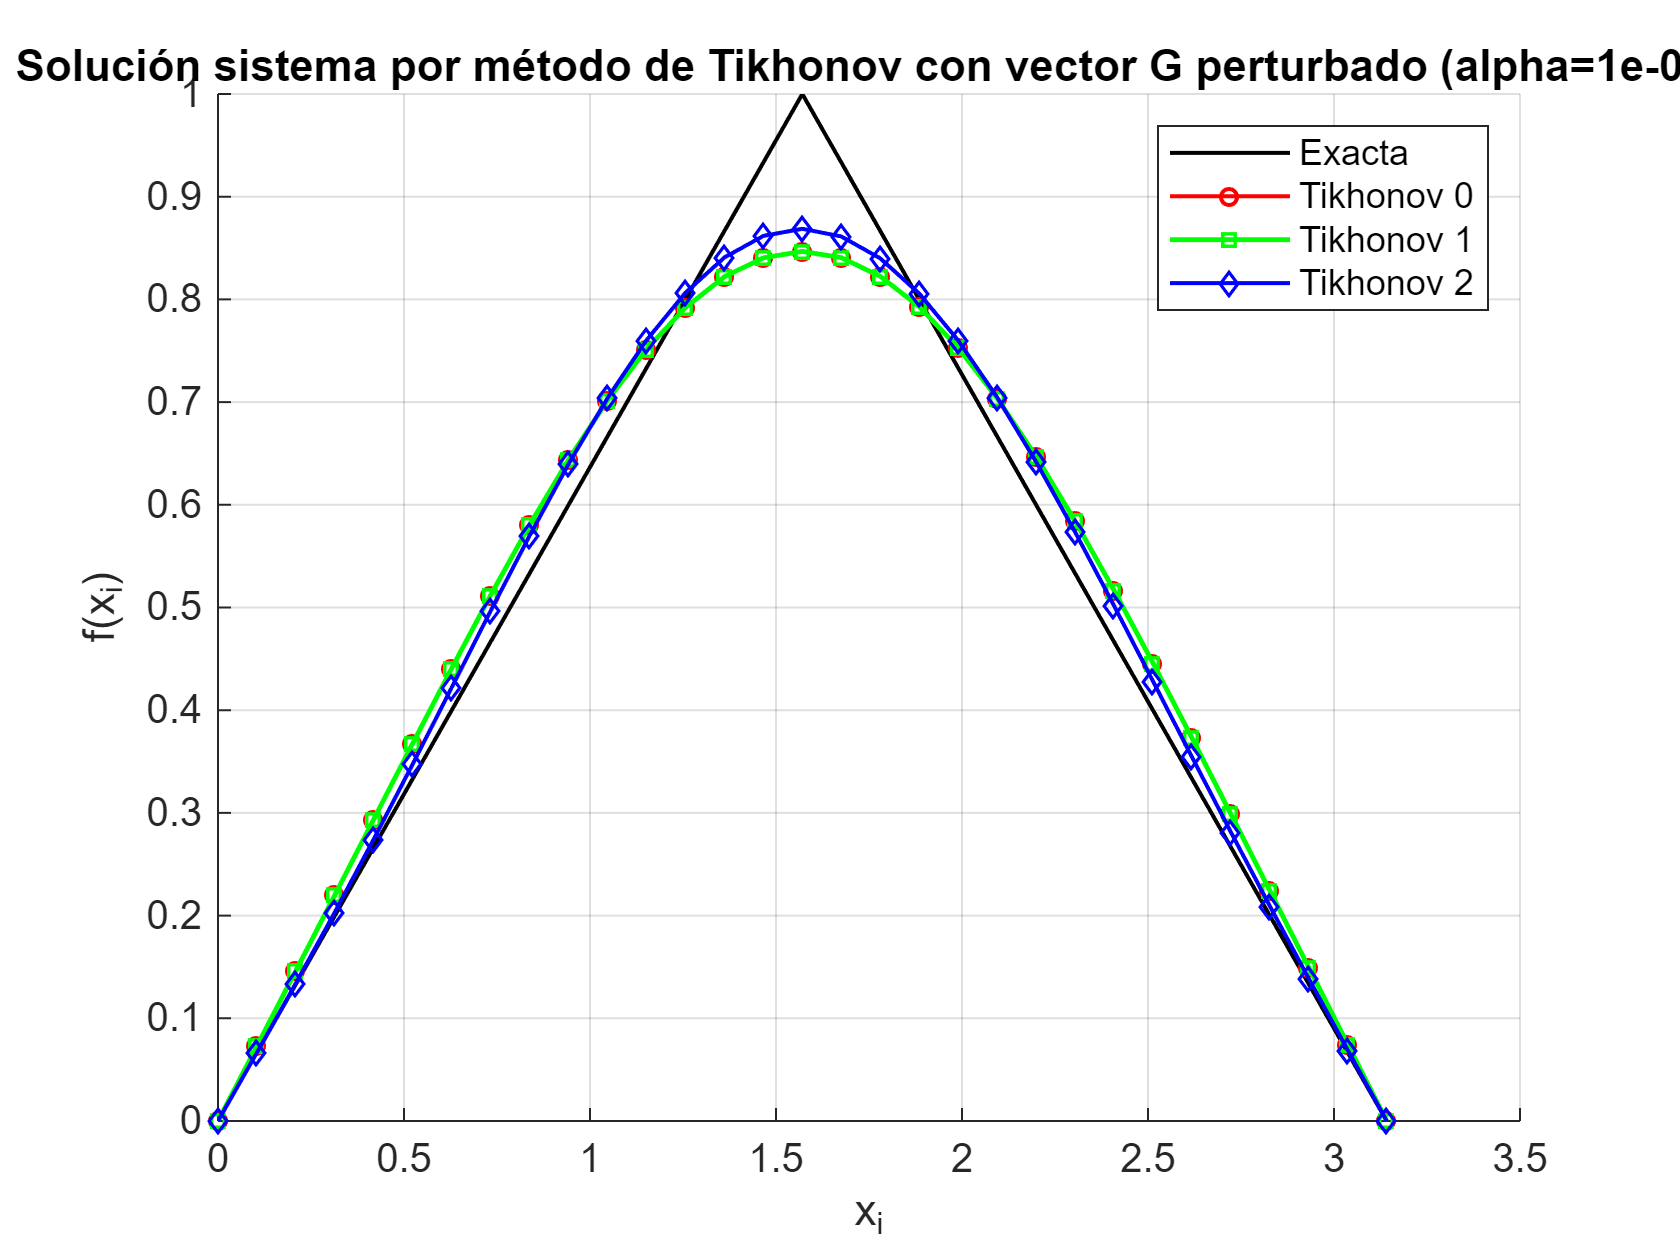

%% Apartado 5 - Perturbación del vector G

load ("datos_T04_M30.mat");

% Matriz A para M=30, N=10, T=0.4
L  = pi;
M  = 30;         
N  = 10;          
T  = 0.4;         
dy = L / M;
yi = (0:M)' * dy;

w = ones(M+1,1);
w(2:end-1) = 2;

% A(i,j)
A = zeros(M+1);
for i = 1:M+1
    x_i = (i-1)*dy;
    for j = 1:M+1
        y_j = (j-1)*dy;
        s = 0;
        for n = 1:N
            s = s + exp(-(n*pi)^2 * T / L^2) * ...
                    sin(n*pi*x_i / L) * sin(n*pi*y_j / L);
        end
        Kij      = (2/L) * s;
        A(i,j)   = (L/(2*M)) * w(j) * Kij;
    end
end

% Perturbación de G con error  |eps_i| <= 0.01*max(G)
rng(0);
eps_max = 0.01 * max(u_aprox);
epsilon = (2*rand(size(u_aprox)) - 1) * eps_max;
G_per = u_aprox + epsilon;

% Solución por Tikhonov y Tikhonov iterado
alpha_per = 1e-3;                
x0_per = tikhonov(A, G_per, alpha_per);             % Tikhonov 
x1_per = tikhonov_iterado(A, G_per, alpha_per,1);   % Tikhonov 1
x2_per = tikhonov_iterado(A, G_per, alpha_per, 2);  % Tikhonov 2

% Solución por Landweber 
mu = 0.95 / norm(A'*A);      
n  = [10, 80, 300];
phi_1 = landweber(A, G_per, mu, n(1));
phi_2 = landweber(A, G_per, mu, n(2));
phi_3 = landweber(A, G_per, mu, n(3));

f_inicial = (2/pi)*xi .* (xi<=pi/2) + (2/pi)*(pi - xi) .* (xi>pi/2);


% Gráfica
figure;
hold on
plot(xi, f_inicial, 'k-', 'LineWidth', 1, 'DisplayName', 'Exacta');
plot(xi, x0_per, 'ro-', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Tikhonov');
plot(xi, x1_per, 'gs-', 'LineWidth', 1.2, 'MarkerSize', 4, 'DisplayName', 'Tikhonov 1');
plot(xi, x2_per, 'bd-', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Tikhonov 2');
legend('Exacta','Tikhonov 0','Tikhonov 1','Tikhonov 2','Location','northeast');
title(sprintf('Solución sistema por método de Tikhonov con vector G perturbado (alpha=%.0e)', alpha_per));
xlabel('x_i'); ylabel('f(x_i)');
grid ('on'); hold off

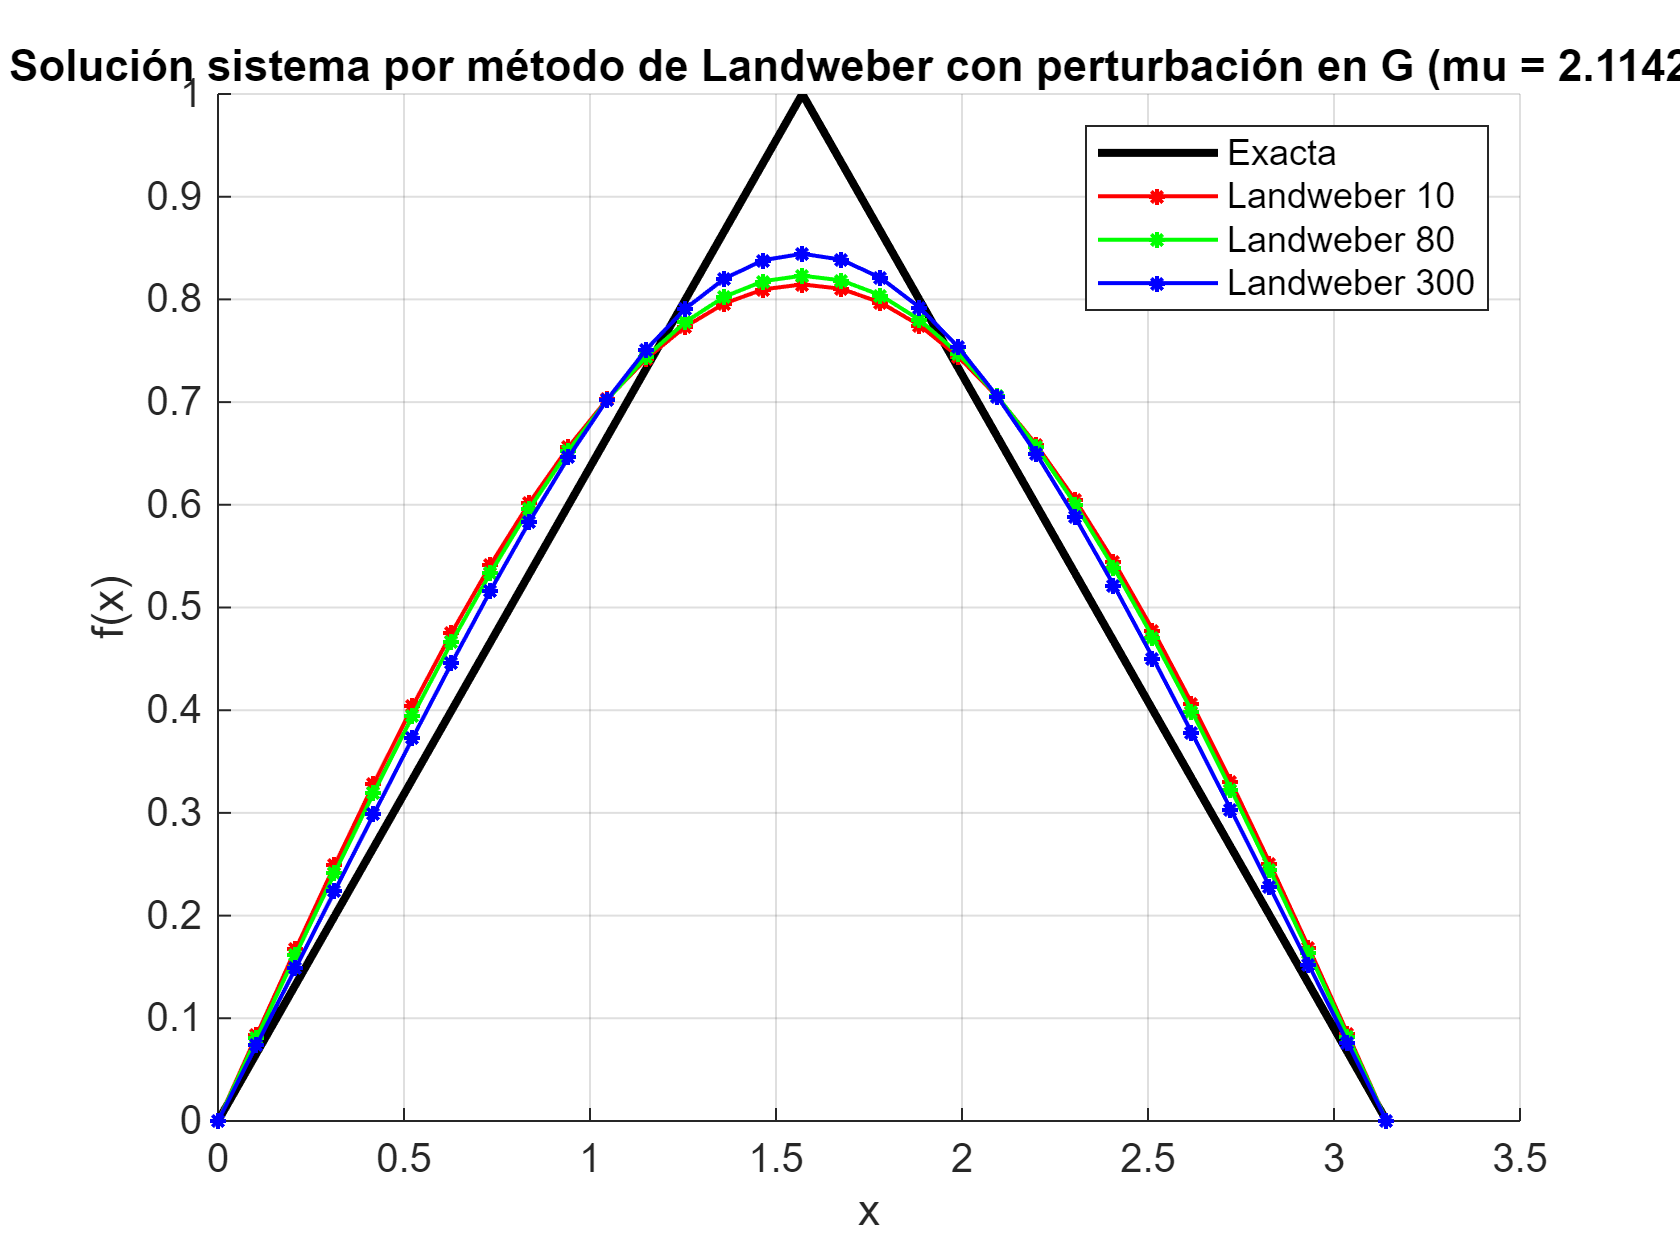


figure
hold on
plot(xi, f_inicial, 'k-', 'LineWidth',2);
plot(xi, phi_1, 'r*-', 'LineWidth',1,'MarkerSize',4);
plot(xi, phi_2, 'g*-', 'LineWidth',1,'MarkerSize',4);
plot(xi, phi_3, 'b*-', 'LineWidth',1,'MarkerSize',4);
legend('Exacta', sprintf('Landweber %d', n(1)), sprintf('Landweber %d', n(2)), sprintf('Landweber %d', n(3)), 'Location','northeast');
title(sprintf('Solución sistema por método de Landweber con perturbación en G (mu = %.5f)', mu));
xlabel('x'); ylabel('f(x)');
grid on; hold off

Ejercicio 2 - Apartado 6

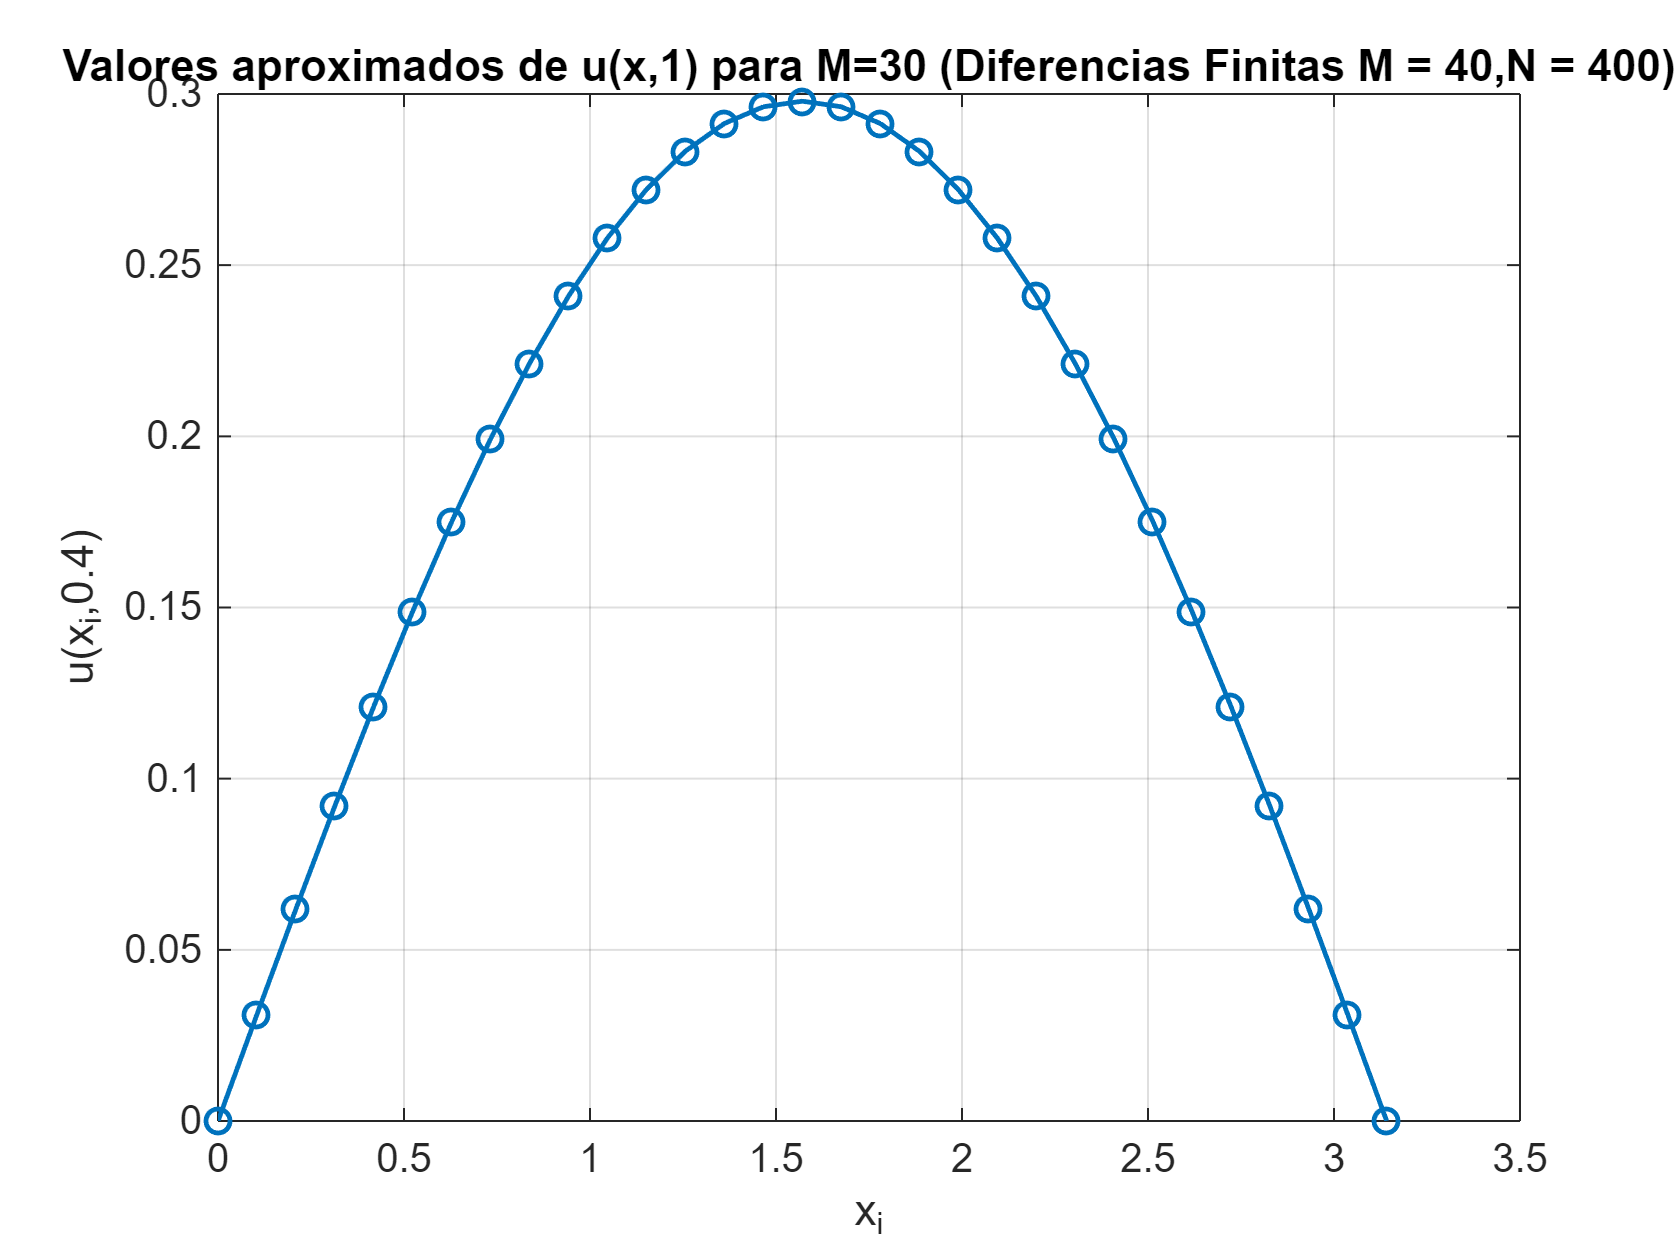

%% Apartado 1 – Aproximación u(x,1) por diferencias finitas

% Parámetros
L = pi;            
Mdf = 40;           
Ndf = 400;           
T = 1;           

dx = L / (Mdf+1);
dt = T / (Ndf+1);
d = dt / dx^2;          % 0 < d < 1/2

% Malla interior para Diferencias Finitas
xDiferenciasFinitas = (1:Mdf)' * dx;

% matriz tridiagonal A_df
e  = ones(Mdf, 1);
A_df = spdiags([d*e, (1-2*d)*e, d*e], -1:1, Mdf, Mdf);

% Condición inicial
fDiferenciasFinitas = (2/pi)*xDiferenciasFinitas .* (xDiferenciasFinitas <= L/2) ...
    + (2/pi)*(L - xDiferenciasFinitas) .* (xDiferenciasFinitas > L/2);

% Iterar esquema Diferecnias Finitas hasta t = 1
% t = (Ndf +1)dt = (Ndf +1)T/(Ndf+1) = T = 1
u = fDiferenciasFinitas;
for j = 1:(Ndf+1)
  u = A_df * u;
end
uDiferenciasFinitas = u;   

% Interpolar en la malla deseada M = 30
M = 30;
xi = (0:M)' * (L/M);      % nodos xi = iL / M, i=0..M

% Construir vector de datos u_aprox en xi
u_aprox = zeros(M+1,1);
u_aprox(2:end-1) = ...
   spline(xDiferenciasFinitas, uDiferenciasFinitas, xi(2:end-1)); %u(0,t)=u(pi,t)=0 

% Fichero
save('datos_T1_M30.mat','xi','u_aprox');

% Gráfica
figure;
plot(xi, u_aprox, 'o-','LineWidth',1.2); xlabel('x_i'); ylabel('u(x_i,0.4)');
title('Valores aproximados de u(x,1) para M=30 (Diferencias Finitas M = 40,N = 400)');
grid on

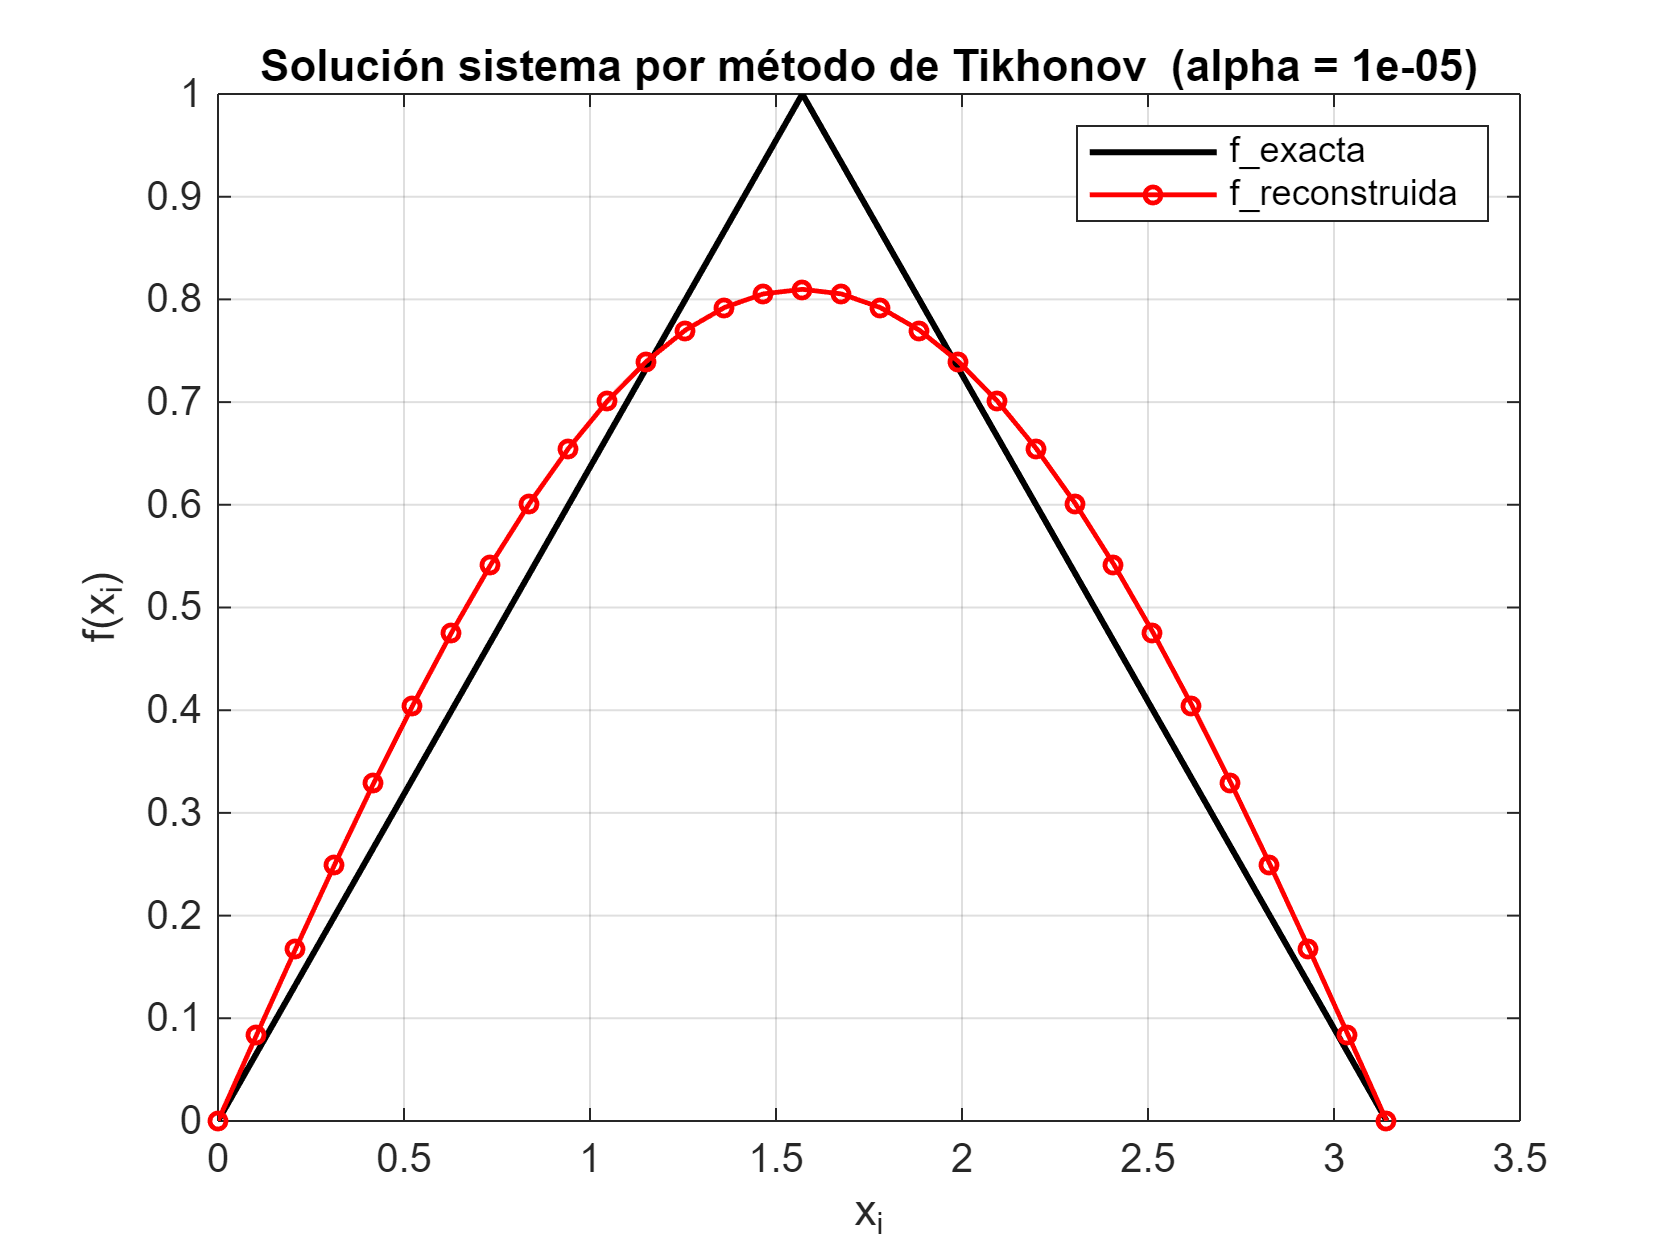


%% Apartado 2 - Resolución sistema AF = G (M = 30 y N = 10) por método de Tikhonov

load('datos_T1_M30.mat','xi','u_aprox')
% Matriz A para M=30, N=10
M  = 30;         
N  = 10;          
dy = L / M;
yi = (0:M)' * dy;

% Trapecio compuesto
w = ones(M+1,1);
w(2:end-1) = 2;

% A(i,j)
A = zeros(M+1);
for i = 1:M+1
    x_i = (i-1)*dy;
    for j = 1:M+1
        y_j = (j-1)*dy;
        s = 0;
        for n = 1:N
            s = s + exp(-(n*pi)^2 * T / L^2) * ...
                    sin(n*pi*x_i / L) * sin(n*pi*y_j / L);
        end
        Kij      = (2/L) * s;
        A(i,j)   = (L/(2*M)) * w(j) * Kij;
    end
end

% Parámetro de Tikhonov y solución regularizada
alpha = 1e-5;                   
G = u_aprox;                    
F = tikhonov(A, G, alpha);  

% Temperatura inicial exacta
f_inicial   = (2/pi)*xi .* (xi<=pi/2) + (2/pi)*(pi - xi) .* (xi>pi/2);

% Representación 
figure
plot(xi, f_inicial, 'k-', 'LineWidth', 1.5), hold on
plot(xi, F,'ro-', 'LineWidth', 1.2, 'MarkerSize',4)
xlabel('x_i'), ylabel('f(x_i)')
legend('f\_exacta','f\_reconstruida'), 
title(sprintf('Solución sistema por método de Tikhonov  (alpha = %.0e)',alpha))
grid on
hold off

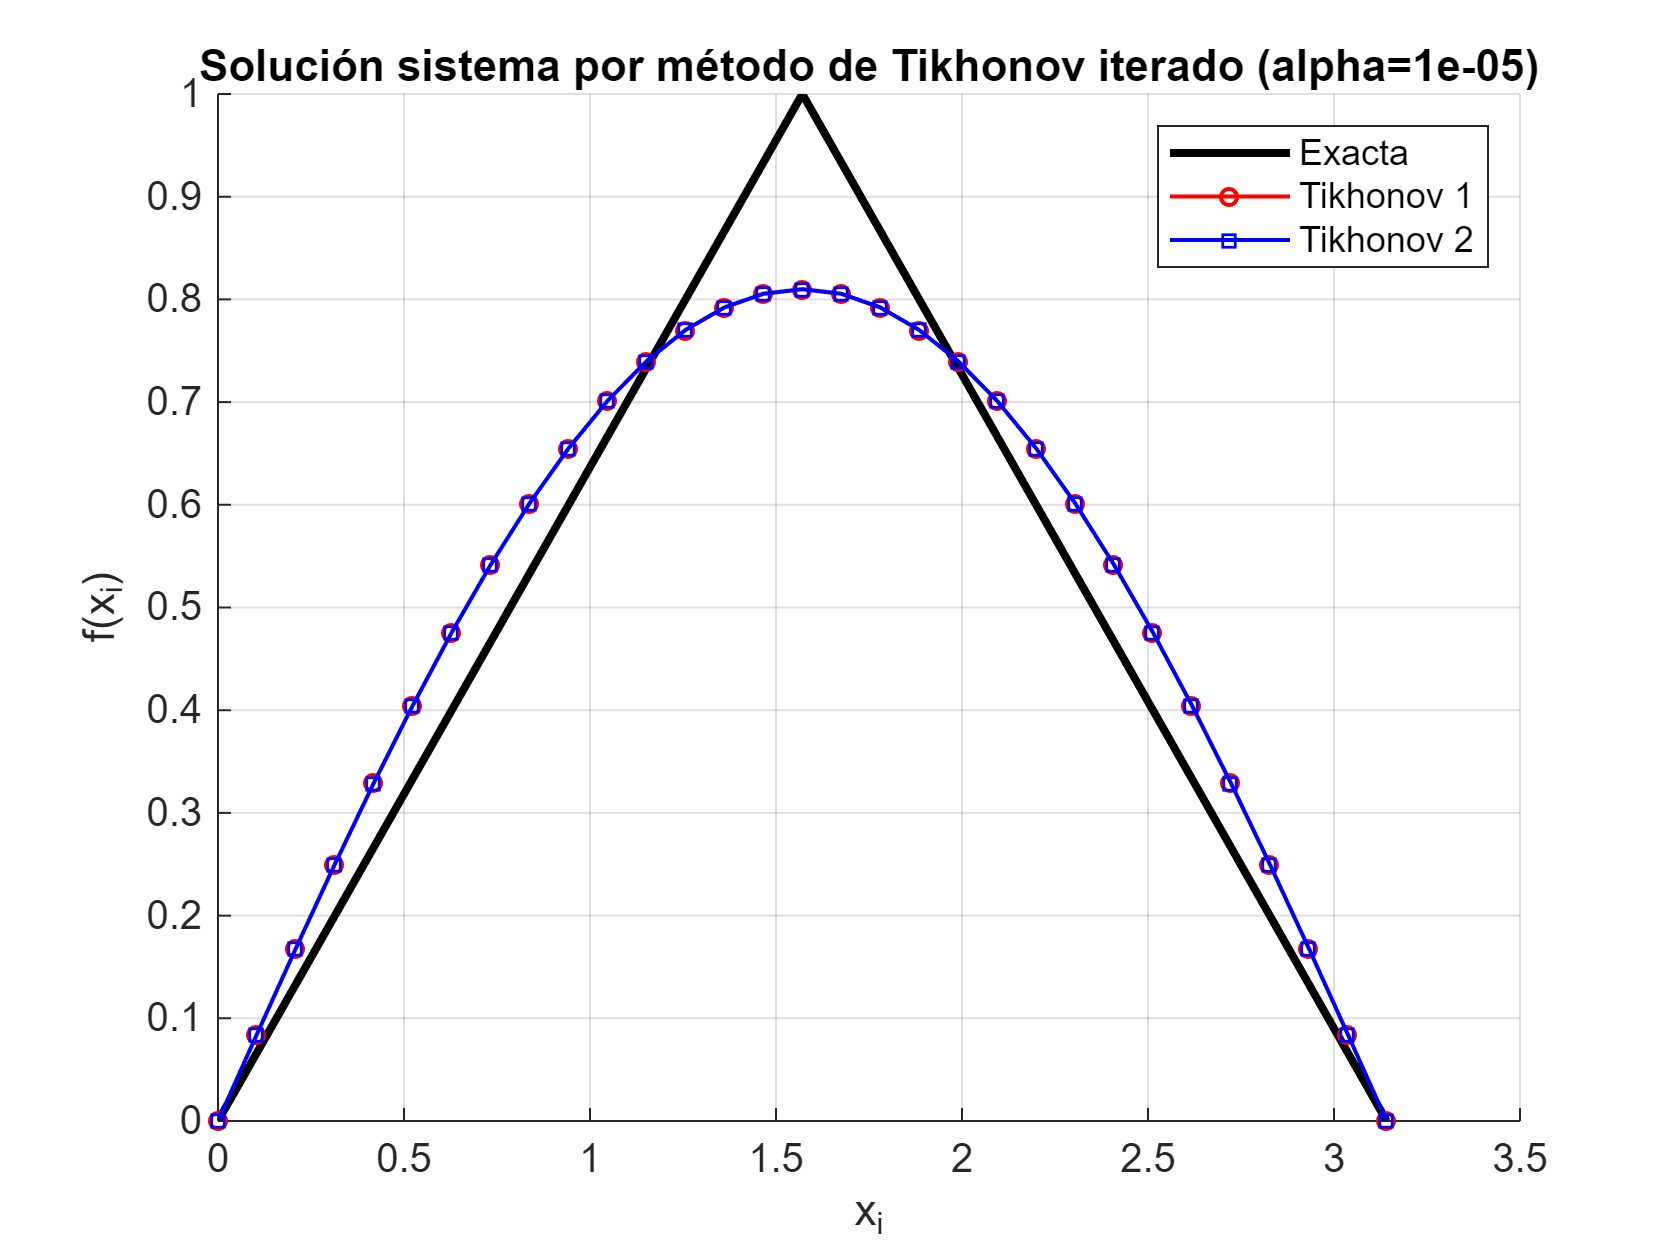


%% Apartado 3 - Resolución sistema AF = G por método de Tikhonov iterado

alpha = 1e-5;  
    

% Tikhonov n = 1 
x_1 = tikhonov_iterado(A, G, alpha, 1);

% Tikhonov n = 2
x_2 = tikhonov_iterado(A, G, alpha, 2);

% Función exacta
f_inicial = (2/pi)*xi .* (xi<=pi/2) + (2/pi)*(pi - xi) .* (xi>pi/2);

% Representación 
figure; hold on
plot(xi, f_inicial,   'k-',  'LineWidth',2);
plot(xi, x_1,   'ro-', 'LineWidth',1, 'MarkerSize',4);
plot(xi, x_2,   'bs-', 'LineWidth',1, 'MarkerSize',4);
legend('Exacta','Tikhonov 1','Tikhonov 2','Location','northeast');
xlabel('x_i'); ylabel('f(x_i)');
title(sprintf('Solución sistema por método de Tikhonov iterado (alpha=%.0e)', alpha));
grid on; hold off

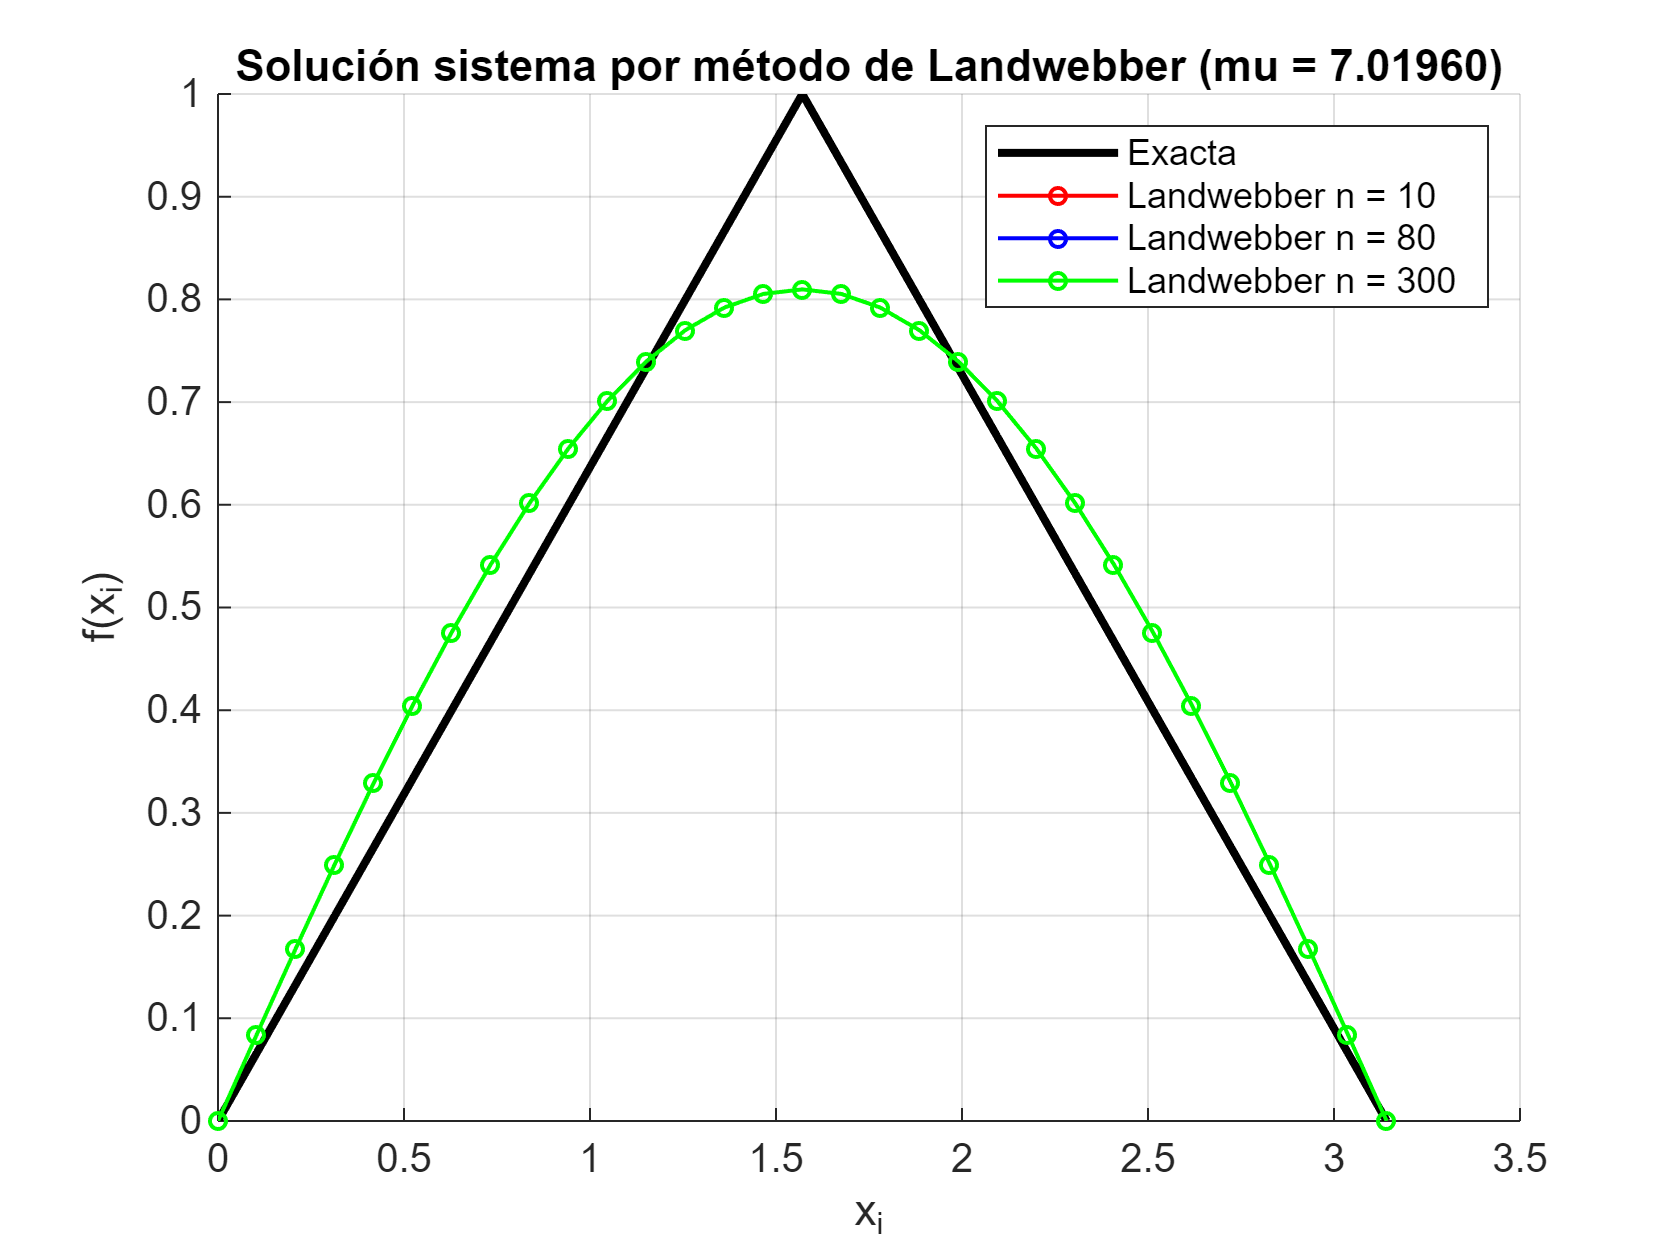


%% Apartado 4 - Resolución sistema AF = G por método de Landwebber

% Elección de mu

mu = 0.95 / norm(A'*A); %<1

% Landwebber n = 10
x_10 = landweber(A, G, mu, 10);

%Landwebber n = 8'
x_80 = landweber(A, G, mu, 80);

%Landwebber n = 300
x_300 = landweber(A, G, mu, 300);

% Función exacta
f_inicial = (2/pi)*xi .* (xi<=pi/2) + (2/pi)*(pi - xi) .* (xi>pi/2);

% Representación 
figure; hold on
plot(xi, f_inicial,   'k-',  'LineWidth',2);
plot(xi, x_10,   'ro-', 'LineWidth',1, 'MarkerSize',4);
plot(xi, x_80,   'bo-', 'LineWidth',1, 'MarkerSize',4);
plot(xi, x_300,  'go-', 'LineWidth',1, 'MarkerSize',4);
legend('Exacta','Landwebber n = 10','Landwebber n = 80','Landwebber n = 300', 'Location','northeast');
xlabel('x_i'); ylabel('f(x_i)');
title(sprintf('Solución sistema por método de Landwebber (mu = %.5f)', mu));
grid on; hold off

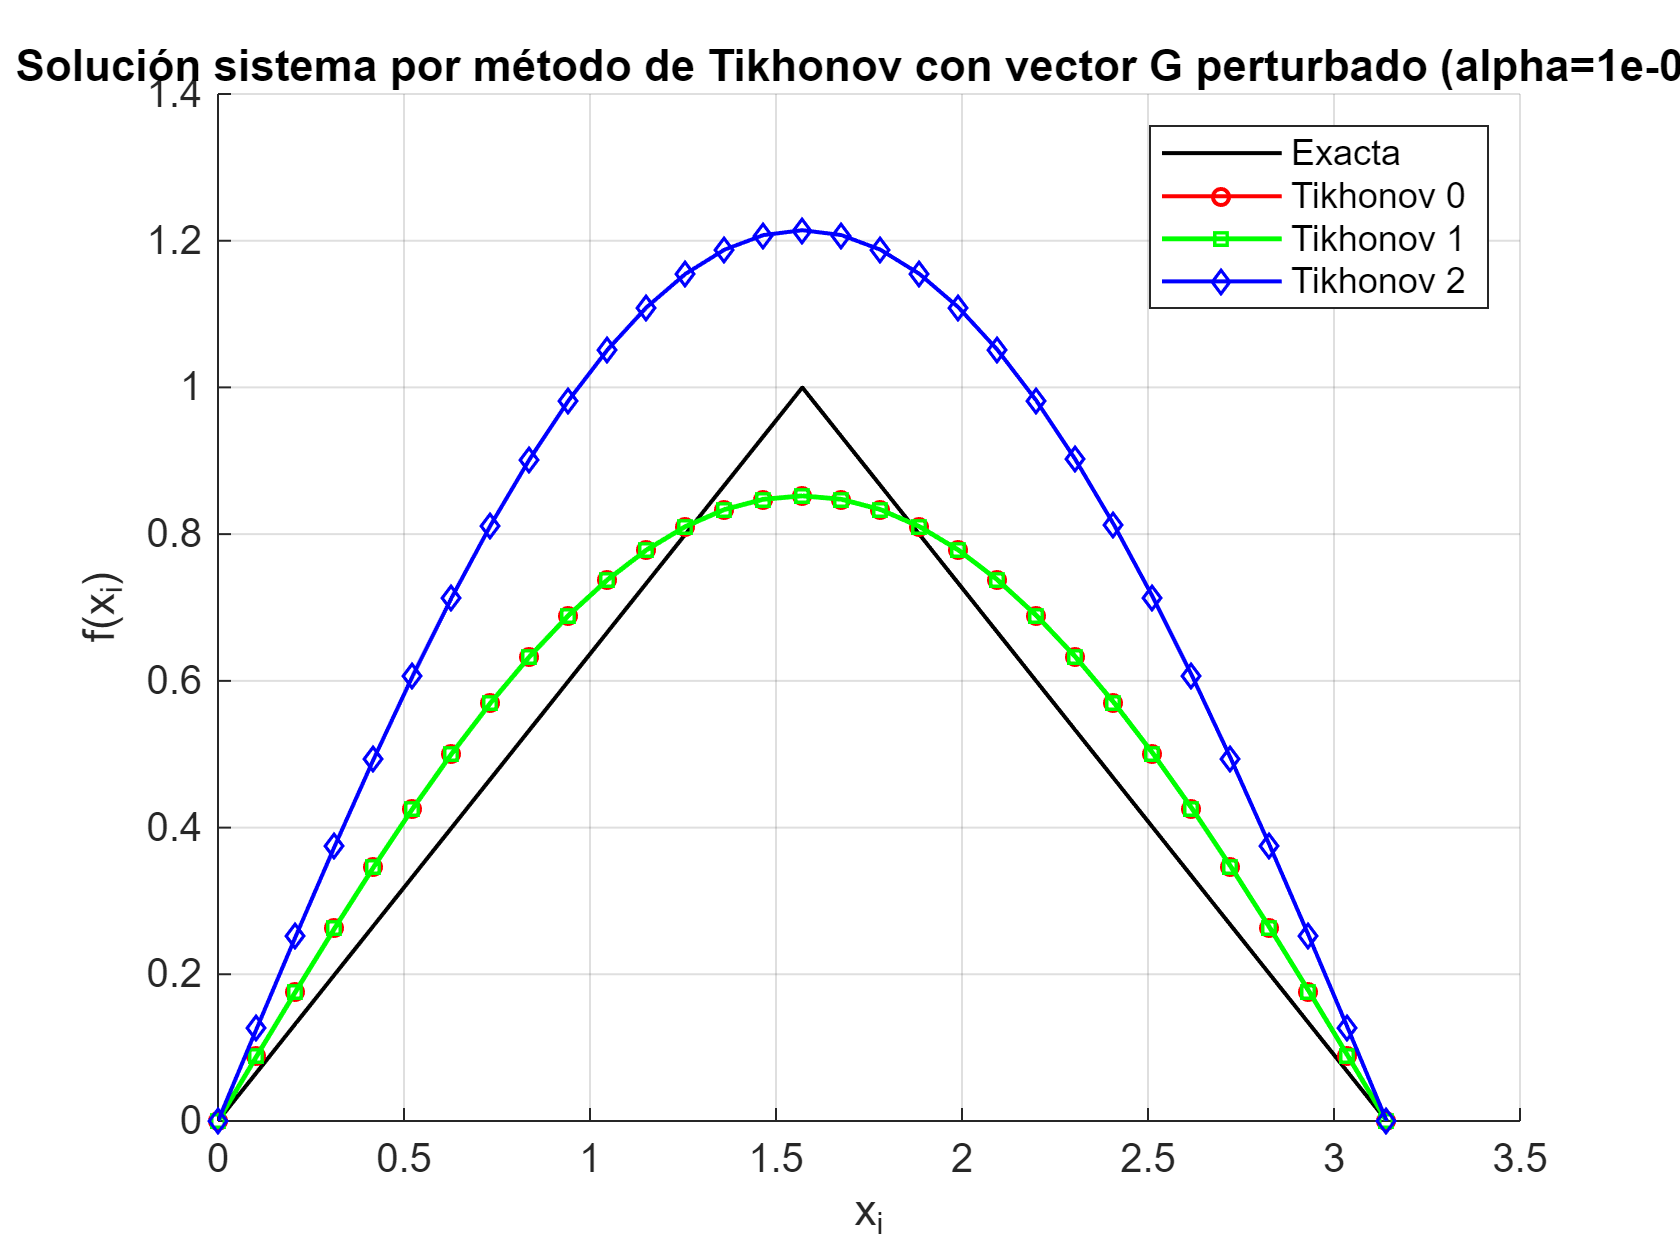


%% Apartado 5 - Perturbación del vector G

load ("datos_T04_M30.mat");

% Matriz A para M=30, N=10, T=1
L  = pi;
M  = 30;         
N  = 10;          
dy = L / M;
yi = (0:M)' * dy;

w = ones(M+1,1);
w(2:end-1) = 2;

% A(i,j)
A = zeros(M+1);
for i = 1:M+1
    x_i = (i-1)*dy;
    for j = 1:M+1
        y_j = (j-1)*dy;
        s = 0;
        for n = 1:N
            s = s + exp(-(n*pi)^2 * T / L^2) * ...
                    sin(n*pi*x_i / L) * sin(n*pi*y_j / L);
        end
        Kij      = (2/L) * s;
        A(i,j)   = (L/(2*M)) * w(j) * Kij;
    end
end

% Perturbación de G con error  |eps_i| <= 0.01*max(G)
rng(0);
eps_max = 0.01 * max(u_aprox);
epsilon = (2*rand(size(u_aprox)) - 1) * eps_max;
G_per = u_aprox + epsilon;

% Solución por Tikhonov y Tikhonov iterado
alpha_per = 1e-1;                
x0_per = tikhonov(A, G_per, alpha_per);             % Tikhonov 0
x1_per = tikhonov_iterado(A, G_per, alpha_per,1);   % Tikhonov 1
x2_per = tikhonov_iterado(A, G_per, alpha_per, 2);  % Tikhonov 2

% Solución por Landweber 
mu = 0.95 / norm(A'*A);      
n  = [10, 80, 300];
phi_1 = landweber(A, G_per, mu, n(1));
phi_2 = landweber(A, G_per, mu, n(2));
phi_3 = landweber(A, G_per, mu, n(3));

f_inicial = (2/pi)*xi .* (xi<=pi/2) + (2/pi)*(pi - xi) .* (xi>pi/2);


% Gráfica
figure
hold on
plot(xi, f_inicial, 'k-', 'LineWidth', 1, 'DisplayName', 'Exacta');
plot(xi, x0_per, 'ro-', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Tikhonov 0');
plot(xi, x1_per, 'gs-', 'LineWidth', 1.2, 'MarkerSize', 4, 'DisplayName', 'Tikhonov 1');
plot(xi, x2_per, 'bd-', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Tikhonov 2');
legend('Exacta','Tikhonov 0','Tikhonov 1','Tikhonov 2','Location','northeast');
title(sprintf('Solución sistema por método de Tikhonov con vector G perturbado (alpha=%.0e)', alpha_per));
xlabel('x_i'); ylabel('f(x_i)');
grid ('on'); hold off

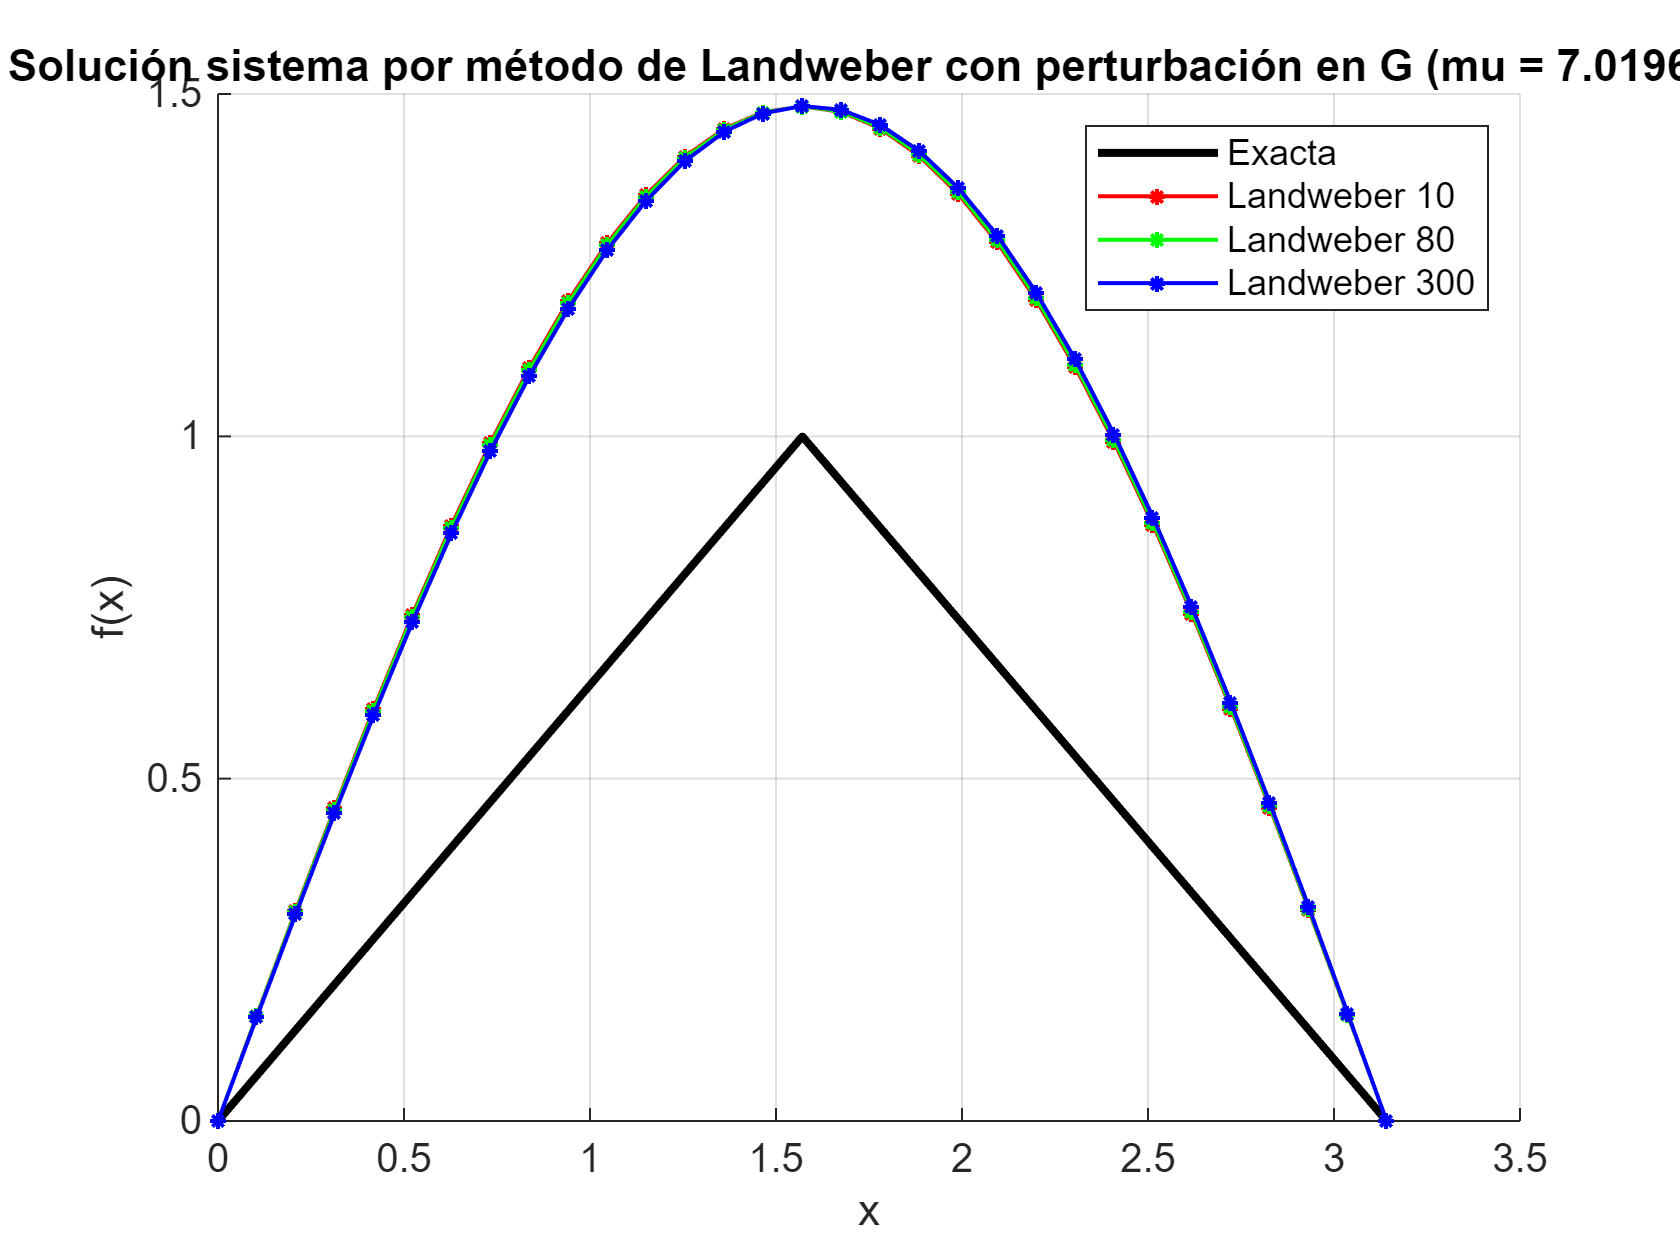


figure
hold on
plot(xi, f_inicial, 'k-', 'LineWidth',2);
plot(xi, phi_1, 'r*-', 'LineWidth',1,'MarkerSize',4);
plot(xi, phi_2, 'g*-', 'LineWidth',1,'MarkerSize',4);
plot(xi, phi_3, 'b*-', 'LineWidth',1,'MarkerSize',4);
legend('Exacta', sprintf('Landweber %d', n(1)), sprintf('Landweber %d', n(2)), sprintf('Landweber %d', n(3)), 'Location','northeast');
title(sprintf('Solución sistema por método de Landweber con perturbación en G (mu = %.5f)', mu));
xlabel('x'); ylabel('f(x)');
grid on; hold off